clc; clear;
addpath("./MMread/")
T = 3;
mean = 0;
sigma = 2;
patch_size = 8

## Reading video from the folder, coverting to grayscale and extrating T = 3 frames


video = mmread ('../cars.avi',1:T);
frames = video.frames;
frames_array = zeros(video.height, video.width, T)

frames_array = frames_array(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

% converting each frame to grayscale
for k = 1 : length(frames)
    frames_array(:,:,k) = im2double(rgb2gray(frames(k).cdata))
end

frames_array = frames_array(:,:,1) =

    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4471    0.4471    0.4667    0.4667    0.4471    0.4471    0.4667    0.4510    0.4980    0.7490    0.6235    0.4588    0.4706    0.4588    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4824    0.4745    0.4824    0.4863    0.4784    0.4706    0.4863    0.5255    0.4745    0.4784    0.4824    0.4824    0.4784    0.4706    0.4588    0.4549    0.4706    0.4784    0.4863    0.4784    0.4706    0.4667    0.4745    0.4863    0.4863    0.4784    0.4784    0.4784    0.4784    0.4745    0.4745    0.4745    0.4667    0.4667    0.4471    0.4824    0.6510    0.5922    0.4588    0.4863    0.4706    0.4667    0.4549    0.4510    0.4471    0.4431    0.4471    0.4471    0.4706    0.4745    0.4824    0.4863    0.4863    0.4824    0.4745    0.4706    0.4706    0.4784    0.4863    0.4941    0.4941    0.4863    0.4784    0.4706  

frames_array = frames_array(:,:,1) =

    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4471    0.4471    0.4667    0.4667    0.4471    0.4471    0.4667    0.4510    0.4980    0.7490    0.6235    0.4588    0.4706    0.4588    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4824    0.4745    0.4824    0.4863    0.4784    0.4706    0.4863    0.5255    0.4745    0.4784    0.4824    0.4824    0.4784    0.4706    0.4588    0.4549    0.4706    0.4784    0.4863    0.4784    0.4706    0.4667    0.4745    0.4863    0.4863    0.4784    0.4784    0.4784    0.4784    0.4745    0.4745    0.4745    0.4667    0.4667    0.4471    0.4824    0.6510    0.5922    0.4588    0.4863    0.4706    0.4667    0.4549    0.4510    0.4471    0.4431    0.4471    0.4471    0.4706    0.4745    0.4824    0.4863    0.4863    0.4824    0.4745    0.4706    0.4706    0.4784    0.4863    0.4941    0.4941    0.4863    0.4784    0.4706  

frames_array = frames_array(:,:,1) =

    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4667    0.4471    0.4471    0.4667    0.4667    0.4471    0.4471    0.4667    0.4510    0.4980    0.7490    0.6235    0.4588    0.4706    0.4588    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4784    0.4824    0.4745    0.4824    0.4863    0.4784    0.4706    0.4863    0.5255    0.4745    0.4784    0.4824    0.4824    0.4784    0.4706    0.4588    0.4549    0.4706    0.4784    0.4863    0.4784    0.4706    0.4667    0.4745    0.4863    0.4863    0.4784    0.4784    0.4784    0.4784    0.4745    0.4745    0.4745    0.4667    0.4667    0.4471    0.4824    0.6510    0.5922    0.4588    0.4863    0.4706    0.4667    0.4549    0.4510    0.4471    0.4431    0.4471    0.4471    0.4706    0.4745    0.4824    0.4863    0.4863    0.4824    0.4745    0.4706    0.4706    0.4784    0.4863    0.4941    0.4941    0.4863    0.4784    0.4706  

imshow(frames_array)
%%Updating frame size
frames_array = frames_array(end-120:end, end-240:end, :)

frames_array = frames_array(:,:,1) =

    0.8431    0.7490    0.5490    0.3608    0.2784    0.2745    0.3451    0.4588    0.5255    0.5020    0.4863    0.5137    0.5569    0.5333    0.4745    0.4706    0.5098    0.5176    0.5490    0.5176    0.3961    0.4235    0.5216    0.4706    0.4157    0.4078    0.4392    0.4118    0.3922    0.4392    0.4235    0.4431    0.4118    0.4235    0.4235    0.4275    0.4471    0.4706    0.4784    0.4667    0.4510    0.4824    0.4902    0.4980    0.4980    0.4941    0.4824    0.4706    0.4627    0.4627    0.5176    0.5451    0.5059    0.4824    0.5020    0.4157    0.2431    0.2745    0.3255    0.3059    0.3451    0.3569    0.3529    0.3294    0.3725    0.3608    0.4431    0.7451    0.9059    0.8745    0.7216    0.4588    0.3333    0.4039    0.4824    0.5373    0.4824    0.3843    0.3059    0.4157    0.4549    0.3961    0.3216    0.4078    0.4196    0.4314    0.4510    0.4510    0.4706    0.4549    0.4510    0.4706    0.4980    0.5020    0.4745    0.4627  

height = size(frames_array, 1)

height = 121

width = size(frames_array, 2)

## Now this subsection will created the coded snapshot I = Ct . Ft

C  = randi([0,1], height, width, T)

C = C(:,:,1) =

     1     1     1     0     0     1     0     0     1     0     1     1     1     1     1     0     0     0     0     0     0     1     0     1     1     1     0     0     1     0     0     1     1     0     0     0     0     0     0     0     0     0     1     1     0     1     1     0     0     1     1     1     1     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     0     1     0     1     1     0     0     0     1     0     0     1     1     1     1     0     1     1     0     1     1     1     1     0     1     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     0     1     1     1     0     0     0     0     1     0     1     1     1     0     1     0     1     1     0     1     0     1     0     1     1     0     0     1     1     0     1     1     1     0     0     0     0     0     0     1     1     0     1     1     1

codedsnapshot = C .* frames_array

codedsnapshot = codedsnapshot(:,:,1) =

    0.4667    0.4667    0.4667         0         0    0.4667         0         0    0.4667         0    0.4471    0.4667    0.4667    0.4471    0.4471         0         0         0         0         0         0    0.4706         0    0.4784    0.4784    0.4784         0         0    0.4784         0         0    0.4784    0.4824         0         0         0         0         0         0         0         0         0    0.4824    0.4824         0    0.4706    0.4588         0         0    0.4784    0.4863    0.4784    0.4706         0         0         0    0.4863    0.4784    0.4784    0.4784    0.4784    0.4745    0.4745    0.4745    0.4667    0.4667    0.4471    0.4824    0.6510    0.5922    0.4588         0    0.4706         0    0.4549         0    0.4471    0.4431         0         0         0    0.4745         0         0    0.4863    0.4824    0.4745    0.4706         0    0.4784    0.4863         0    0.4941    0.4863    0.4784    0.4706

I = zeros(height,width)

I =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i = 1: T
    I = I+ codedsnapshot(:,:,i)
    
end

I =     0.4667    0.4667    0.4667         0         0    0.4667         0         0    0.4667         0    0.4471    0.4667    0.4667    0.4471    0.4471         0         0         0         0         0         0    0.4706         0    0.4784    0.4784    0.4784         0         0    0.4784         0         0    0.4784    0.4824         0         0         0         0         0         0         0         0         0    0.4824    0.4824         0    0.4706    0.4588         0         0    0.4784
    0.3373    0.3373         0         0    0.3373    0.3373    0.3373         0    0.3216    0.3176    0.3176         0         0    0.3176         0         0         0         0    0.6000    0.4980    0.3412         0         0         0         0         0    0.3333    0.3333    0.3333         0    0.3333    0.3333    0.3176    0.3098    0.3490    0.3373    0.3294         0         0    0.3333         0         0         0    0.3412         0         0         0    0.3137    0.3333    0

I =     0.9373    0.9373    0.9451    0.4784         0    0.9373    0.4588    0.4431    0.4667    0.4667    0.9216    0.4667    0.4667    0.4471    0.8941         0    0.7451    0.6667    0.4784         0    0.4588    0.9490    0.4824    0.4784    0.9608    0.9608         0    0.4784    0.4784    0.4745         0    0.9490    0.9804    0.4784    0.4784         0    0.4745         0    0.4784    0.4980    0.4667         0    0.9529    0.4824         0    0.4706    0.4588    0.4980    0.4863    0.4784
    0.6706    0.6706    0.3373    0.3373    0.3373    0.6667    0.6510    0.3020    0.6431    0.3176    0.3176         0         0    0.6275    0.3176         0    0.5882    0.5294    0.9569    0.4980    0.6824    0.3451    0.3412         0    0.3216    0.3216    0.3333    0.3333    0.6667    0.3373    0.6627    0.3333    0.3176    0.3098    0.3490    0.3373    0.3294    0.3294    0.3333    0.6784    0.3490         0    0.3373    0.3412         0         0    0.3294    0.6510    0.3333    0

I =     1.4118    0.9373    1.4353    0.9412         0    1.3882    0.4588    0.4431    0.9373    0.4667    0.9216    0.4667    0.9098    0.8941    0.8941    0.6941    0.7451    1.1412    0.9451    0.4784    0.4588    0.9490    0.9647    0.9529    1.4431    0.9608         0    0.9451    0.9569    0.4745    0.4745    0.9490    1.4667    0.9647    0.4784         0    0.9412         0    0.4784    0.4980    0.4667    0.4745    0.9529    0.4824         0    0.9569    0.4588    0.4980    0.9608    0.4784
    1.0157    0.6706    0.6706    0.6627    0.6549    0.6667    0.9608    0.6353    0.9647    0.6353    0.6314         0    0.3098    0.9529    0.8824         0    0.9529    0.5294    1.2902    0.4980    0.6824    0.6824    0.6549         0    0.6392    0.6588    0.3333    0.3333    0.6667    0.3373    0.6627    0.3333    0.6431    0.6275    0.6667    0.3373    0.6745    0.3294    0.6706    1.0235    0.3490    0.3333    0.6627    0.6627         0    0.3451    0.6824    0.9804    0.3333    1

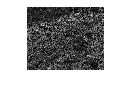

imshow(mat2gray(I))

## Adding gausssian noise to the codedsnapshot

noise = normrnd(0, sigma/255, height, width)

noise =    -0.0029   -0.0072    0.0015   -0.0072   -0.0019   -0.0096   -0.0052   -0.0002    0.0027   -0.0066   -0.0066    0.0210    0.0060   -0.0054    0.0136   -0.0070    0.0035   -0.0062   -0.0061   -0.0049    0.0006    0.0004   -0.0021    0.0119    0.0013    0.0108   -0.0190    0.0122   -0.0011   -0.0021   -0.0163   -0.0078    0.0025    0.0114   -0.0091    0.0007   -0.0020    0.0013    0.0144    0.0009    0.0060    0.0109    0.0180   -0.0081    0.0206   -0.0112    0.0041   -0.0037   -0.0091    0.0131
   -0.0039    0.0048    0.0015   -0.0032    0.0037    0.0008   -0.0001   -0.0028   -0.0066   -0.0018   -0.0144   -0.0088   -0.0059    0.0023    0.0068   -0.0095   -0.0018    0.0188   -0.0022   -0.0011    0.0052   -0.0016   -0.0095   -0.0031   -0.0108    0.0046   -0.0017   -0.0012   -0.0041   -0.0000   -0.0072    0.0114    0.0140    0.0038    0.0034    0.0037   -0.0050   -0.0039   -0.0113    0.0025   -0.0119    0.0043   -0.0027   -0.0149   -0.0132    0.0011   -0.0070    0.0112   -0.0141 

I_final = I + noise

I_final =     1.4089    0.9301    1.4368    0.9339   -0.0019    1.3786    0.4536    0.4430    0.9399    0.4600    0.9150    0.4877    0.9158    0.8887    0.9077    0.6871    0.7486    1.1349    0.9390    0.4735    0.4595    0.9494    0.9626    0.9648    1.4445    0.9716   -0.0190    0.9573    0.9558    0.4724    0.4582    0.9412    1.4692    0.9761    0.4693    0.0007    0.9391    0.0013    0.4928    0.4990    0.4726    0.4854    0.9709    0.4743    0.0206    0.9456    0.4629    0.4944    0.9517    0.4915
    1.0118    0.6754    0.6721    0.6596    0.6586    0.6675    0.9606    0.6325    0.9581    0.6335    0.6170   -0.0088    0.3039    0.9552    0.8892   -0.0095    0.9511    0.5482    1.2880    0.4970    0.6875    0.6807    0.6454   -0.0031    0.6285    0.6634    0.3317    0.3322    0.6626    0.3372    0.6556    0.3448    0.6571    0.6313    0.6701    0.3410    0.6695    0.3255    0.6593    1.0261    0.3371    0.3377    0.6601    0.6478   -0.0132    0.3462    0.6754    0.9916    0.319

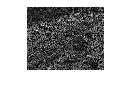

imshow(mat2gray(I_final))

## Patchwise reconstruction

dct = dctmtx(patch_size);
psi = kron(dct', dct);
psi_t = kron(eye(T), psi)

psi_t =     0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1734    0.1734    0.1734    0.1734    0.1734    0.1734    0.1734    0.1734    0.1633    0.1633    0.1633    0.1633    0.1633    0.1633    0.1633    0.1633    0.1470    0.1470    0.1470    0.1470    0.1470    0.1470    0.1470    0.1470    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0982    0.0676    0.0676
    0.1734    0.1470    0.0982    0.0345   -0.0345   -0.0982   -0.1470   -0.1734    0.2405    0.2039    0.1362    0.0478   -0.0478   -0.1362   -0.2039   -0.2405    0.2265    0.1920    0.1283    0.0451   -0.0451   -0.1283   -0.1920   -0.2265    0.2039    0.1728    0.1155    0.0406   -0.0406   -0.1155   -0.1728   -0.2039    0.1734    0.1470    0.0982    0.0345   -0.0345   -0.0982   -0.1470   -0.1734    0.1362    0.1155    0.0772    0.0271   -0.0271   -0.0772   -0.1155   -0.1362    0.0938 

f_reconst = zeros(height, width, T);
count = zeros(height, width, T);
%% patch wise reconstruction
for i = 1:height - patch_size + 1
    for j = 1: width - patch_size + 1
        
        %% \Phi_t is a diagonal matrix and f_t is 
        % the t-th vectorized frame.
        % y has n pixels, and so does each 
        % f_t and each \Phi_t is a n x n diagonal matrix. 
        patch = I(i:i+patch_size-1, j:j+patch_size-1)
        patch_S = C(i:i+patch_size-1, j:j+patch_size-1,:)
        % \Phi_{it} is a p^2 times p^2 diagonal matrix
        phi = []
        for t = 1:T
            st = patch_S(:,:,t)
            phi=[phi diag(st(:))]
        end

        A = phi * psi_t'


        %% f_{it} is a p x p patch from the t-th frame 
        % but expressed as a vector of size p^2 by 1
        % y_i is also a p^2 times 1 vector.
        y = reshape(patch, patch_size^2, 1)

        %% theta_i is a vector of size Tp^2 by 1 
        % obtained by concatenating all T vectors theta_{it}
        theta = OMP(A, y, 0.1)
        I_t = psi_t' * theta
        for t = 1: T
        f_t = reshape(I_t((k-1)*patch_size^2+1:k*patch_size^2,:), patch_size ,patch_size);
        f_reconst(i:i+patch_size-1, j: j+patch_size-1, t) = f_reconst(i:i+patch_size-1, j: j+patch_size-1, t) + f_t
            
        %% Repeat the reconstruction for all overlapping 
        % patches and average across the overlapping 
        % pixels to yield the final reconstruction.
        count(i:i+patch_size-1, j: j+patch_size-1, t) = count(i:i+patch_size-1, j: j+patch_size-1, t) + ones(patch_size, patch_size)
        end
        
    end
end

patch =     1.4118    0.9373    1.4353    0.9412         0    1.3882    0.4588    0.4431
    1.0157    0.6706    0.6706    0.6627    0.6549    0.6667    0.9608    0.6353
    0.6235    0.3098    0.6039    0.3020         0    0.5765    0.5882    0.6000
    0.6039         0    0.3020    0.9137    0.5961    0.3020    0.9098    0.3255
    0.2941    0.5686    0.5686    0.5569    0.5765    0.2784    0.2824    0.3020
    0.3098         0    0.6078         0    0.6039    0.9098    0.3059    0.3059
    0.3176    0.3216    0.9490         0    0.3059    0.6235    0.3098    0.8902
    0.3176    0.3098    0.3059         0    0.6431    0.3137    0.5882    0.8824


patch_S = patch_S(:,:,1) =

     1     1     1     0     0     1     0     0
     1     1     0     0     1     1     1     0
     0     0     1     1     0     0     1     0
     1     0     1     1     1     1     1     0
     1     1     1     0     1     0     0     0
     0     0     1     0     1     1     1     1
     0     0     1     0     0     1     1     1
     1     0     0     0     1     0     0     1


patch_S(:,:,2) =

     1     1     1     1     0     1     1     1
     1     1     1     1     0     1     1     1
     1     1     0     0     0     1     0     1
     0     0     0     1     1     0     1     0
     0     0     0     1     0     1     1     1
     0     0     0     0     0     1     0     0
     1     0     1     0     0     1     0     1
     0     0     0     0     1     1     1     1


patch_S(:,:,3) =

     1     0     1     1     0     1     0     0
     1     0     1     1     1     0     1     1
     1     0     1     0     0     1     1     1
 


phi =

     []



st =      1     1     1     0     0     1     0     0
     1     1     0     0     1     1     1     0
     0     0     1     1     0     0     1     0
     1     0     1     1     1     1     1     0
     1     1     1     0     1     0     0     0
     0     0     1     0     1     1     1     1
     0     0     1     0     0     1     1     1
     1     0     0     0     1     0     0     1


phi =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

st =      1     1     1     1     0     1     1     1
     1     1     1     1     0     1     1     1
     1     1     0     0     0     1     0     1
     0     0     0     1     1     0     1     0
     0     0     0     1     0     1     1     1
     0     0     0     0     0     1     0     0
     1     0     1     0     0     1     0     1
     0     0     0     0     1     1     1     1


phi =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

st =      1     0     1     1     0     1     0     0
     1     0     1     1     1     0     1     1
     1     0     1     0     0     1     1     1
     1     0     0     1     0     0     1     1
     0     1     1     1     1     0     0     0
     1     0     1     0     1     1     0     0
     0     1     1     0     1     0     0     1
     0     1     1     0     0     0     1     1


phi =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0 

A =     0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0

y =     1.4118
    1.0157
    0.6235
    0.6039
    0.2941
    0.3098
    0.3176
    0.3176
    0.9373
    0.6706


r =     1.4118
    1.0157
    0.6235
    0.6039
    0.2941
    0.3098
    0.3176
    0.3176
    0.9373
    0.6706


theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 65

T = 65

i = 1

theta =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r =     0.6660
    0.2699
   -0.1223
    0.6039
    0.2941
    0.3098
   -0.4281
    0.3176
   -0.0972
   -0.3639


j = 1

T =      1    65


i = 2

theta =     3.3795
         0
         0
         0
         0
         0
         0
         0
         0
         0


r =     0.4771
    0.0811
    0.1113
    0.1815
   -0.1283
    0.3098
   -0.1945
   -0.1048
   -0.3591
   -0.6258


j = 129

T =      1    65   129


i = 3

theta =     2.4029
         0
         0
         0
         0
         0
         0
         0
         0
         0


r =     0.4155
    0.0194
   -0.0724
    0.0254
   -0.0062
    0.0316
   -0.1001
    0.0173
   -0.0588
   -0.3255


j = 81

T =      1    65    81   129


i = 4

theta =     2.2876
         0
         0
         0
         0
         0
         0
         0
         0
         0


r =     0.2501
   -0.1460
   -0.2522
    0.0080
    0.0082
   -0.0002
   -0.2481
    0.0317
   -0.1349
   -0.4016


j = 9

T =      1     9    65    81   129


i = 5

theta =     2.2578
         0
         0
         0
         0
         0
         0
         0
   -1.0308
         0


r =     0.3884
   -0.0077
   -0.2465
    0.1335
    0.1407
   -0.0073
   -0.2353
    0.1643
    0.0379
   -0.2288


j = 69

T =      1     9    65    69    81   129


i = 6

theta =     2.1306
         0
         0
         0
         0
         0
         0
         0
   -1.0249
         0


r =     0.2551
    0.0891
   -0.1649
    0.1388
    0.1559
   -0.0171
   -0.1438
    0.1794
   -0.1208
   -0.0684


j = 130

T =      1     9    65    69    81   129   130


i = 7

theta =     2.1216
         0
         0
         0
         0
         0
         0
         0
   -1.0512
         0


r =     0.1538
   -0.0038
   -0.2267
    0.0973
    0.1603
    0.0333
   -0.1136
    0.1838
   -0.0529
   -0.0154


j = 17

T =      1     9    17    65    69    81   129   130


i = 8

theta =     2.1035
         0
         0
         0
         0
         0
         0
         0
   -1.0318
         0


r =     0.1085
   -0.0394
   -0.1828
    0.0160
    0.0772
    0.0255
   -0.0760
    0.1007
   -0.1025
   -0.0489


j = 177

T =      1     9    17    65    69    81   129   130   177


i = 9

theta =     2.1377
         0
         0
         0
         0
         0
         0
         0
   -1.1413
         0


r =     0.0721
   -0.0599
   -0.2182
   -0.0481
    0.0855
   -0.0649
   -0.0476
    0.1091
   -0.0803
    0.0004


j = 131

T =      1     9    17    65    69    81   129   130   131   177


i = 10

theta =     2.3402
         0
         0
         0
         0
         0
         0
         0
   -1.1423
         0


r =     0.0031
   -0.0892
   -0.1603
    0.0189
    0.0655
   -0.0294
   -0.0300
    0.0890
   -0.0769
   -0.0073


j = 89

T =      1     9    17    65    69    81    89   129   130   131   177


i = 11

theta =     2.4515
         0
         0
         0
         0
         0
         0
         0
   -1.1881
         0


r =     0.0781
   -0.0283
   -0.0943
    0.0236
    0.0571
   -0.0196
    0.0196
    0.0806
   -0.0693
   -0.0164


j = 161

T =      1     9    17    65    69    81    89   129   130   131   161   177


i = 12

theta =     2.5270
         0
         0
         0
         0
         0
         0
         0
   -1.1719
         0


r =     0.0304
   -0.0813
   -0.1302
   -0.0144
    0.0478
   -0.0610
    0.0167
    0.0713
   -0.0688
   -0.0314


j = 137

T =      1     9    17    65    69    81    89   129   130   131   137   161   177


i = 13

theta =     2.5537
         0
         0
         0
         0
         0
         0
         0
   -0.8510
         0


r =     0.0651
   -0.0509
   -0.0466
    0.0148
    0.0001
   -0.0007
    0.0249
    0.0236
   -0.0971
   -0.0717


j = 42

T = 1×14
     1     9    17    42    65    69    81    89   129   130   131   137   161   177


i = 14

theta = 192×1
    2.5692
         0
         0
         0
         0
         0
         0
         0
   -0.7889
         0


r = 64×1
    0.0140
   -0.0905
   -0.0245
    0.0123
    0.0010
    0.0202
    0.0305
    0.0703
   -0.0601
   -0.0404


j = 74

T = 1×15
     1     9    17    42    65    69    74    81    89   129   130   131   137   161   177


i = 15

theta = 192×1
    2.6129
         0
         0
         0
         0
         0
         0
         0
   -0.7321
         0


r = 64×1
    0.0168
   -0.0844
   -0.0069
   -0.0005
   -0.0136
    0.0183
   -0.0180
    0.0617
   -0.0441
   -0.0225


j = 75

T = 1×16
     1     9    17    42    65    69    74    75    81    89   129   130   131   137   161   177


i = 16

theta = 192×1
    2.6247
         0
         0
         0
         0
         0
         0
         0
   -0.6889
         0


r = 64×1
    0.0451
   -0.0749
   -0.0235
   -0.0117
   -0.0237
    0.0184
   -0.0034
    0.0482
   -0.0267
   -0.0220


j = 51

T = 1×17
     1     9    17    42    51    65    69    74    75    81    89   129   130   131   137   161   177


i = 17

theta = 192×1
    2.6524
         0
         0
         0
         0
         0
         0
         0
   -0.6660
         0


r = 64×1
    0.0257
   -0.0823
   -0.0183
    0.0243
    0.0079
    0.0196
    0.0054
    0.0041
    0.0104
   -0.0187


j = 77

T = 1×18
     1     9    17    42    51    65    69    74    75    77    81    89   129   130   131   137   161   177


i = 18

theta = 192×1
    2.6039
         0
         0
         0
         0
         0
         0
         0
   -0.6594
         0


r = 64×1
   -0.0046
   -0.0510
   -0.0079
    0.0389
    0.0232
    0.0195
    0.0216
    0.0058
   -0.0344
    0.0088


j = 52

T = 1×19
     1     9    17    42    51    52    65    69    74    75    77    81    89   129   130   131   137   161   177


i = 19

theta = 192×1
    2.6502
         0
         0
         0
         0
         0
         0
         0
   -0.6497
         0


r = 64×1
   -0.0278
   -0.0292
   -0.0183
    0.0488
   -0.0124
   -0.0000
    0.0299
    0.0223
    0.0014
   -0.0203


j = 105

T = 1×20
     1     9    17    42    51    52    65    69    74    75    77    81    89   105   129   130   131   137   161   177


i = 20

theta = 192×1
    2.5633
         0
         0
         0
         0
         0
         0
         0
   -0.6222
         0


r = 64×1
   -0.0120
   -0.0182
   -0.0063
    0.0358
   -0.0107
    0.0016
    0.0402
    0.0336
   -0.0139
   -0.0259


j = 108

T = 1×21
     1     9    17    42    51    52    65    69    74    75    77    81    89   105   108   129   130   131   137   161   177


i = 21

theta = 192×1
    2.5599
         0
         0
         0
         0
         0
         0
         0
   -0.6131
         0


r = 64×1
    0.0001
   -0.0287
   -0.0288
    0.0311
   -0.0111
   -0.0021
    0.0424
    0.0361
   -0.0275
   -0.0186


j = 171

T = 1×22
     1     9    17    42    51    52    65    69    74    75    77    81    89   105   108   129   130   131   137   161   171   177


i = 22

theta = 192×1
    2.5421
         0
         0
         0
         0
         0
         0
         0
   -0.6638
         0


r = 64×1
   -0.0112
   -0.0297
   -0.0216
    0.0499
   -0.0108
   -0.0070
    0.0461
    0.0432
   -0.0278
   -0.0155


j = 61

T = 1×23
     1     9    17    42    51    52    61    65    69    74    75    77    81    89   105   108   129   130   131   137   161   171   177


i = 23

theta = 192×1
    2.5068
         0
         0
         0
         0
         0
         0
         0
   -0.6693
         0


r = 64×1
   -0.0116
   -0.0159
   -0.0246
    0.0285
   -0.0190
   -0.0077
    0.0450
    0.0297
   -0.0094
   -0.0242


j = 149

T = 1×24
     1     9    17    42    51    52    61    65    69    74    75    77    81    89   105   108   129   130   131   137   149   161   171   177


i = 24

theta = 192×1
    2.4837
         0
         0
         0
         0
         0
         0
         0
   -0.6861
         0


r = 64×1
   -0.0271
    0.0041
   -0.0161
    0.0121
   -0.0171
   -0.0015
    0.0443
    0.0384
   -0.0113
   -0.0173


j = 143

T = 1×25
     1     9    17    42    51    52    61    65    69    74    75    77    81    89   105   108   129   130   131   137   143   149   161   171   177


i = 25

theta = 192×1
    2.4954
         0
         0
         0
         0
         0
         0
         0
   -0.7033
         0


r = 64×1
   -0.0246
   -0.0119
   -0.0075
   -0.0024
   -0.0185
    0.0120
    0.0445
    0.0419
   -0.0109
   -0.0118


j = 101

T = 1×26
     1     9    17    42    51    52    61    65    69    74    75    77    81    89   101   105   108   129   130   131   137   143   149   161   171   177


i = 26

theta = 192×1
    2.4902
         0
         0
         0
         0
         0
         0
         0
   -0.7323
         0


r = 64×1
   -0.0105
   -0.0112
   -0.0057
   -0.0063
   -0.0154
    0.0173
    0.0335
    0.0493
   -0.0158
   -0.0042


j = 134

T = 1×27
     1     9    17    42    51    52    61    65    69    74    75    77    81    89   101   105   108   129   130   131   134   137   143   149   161   171   177


i = 27

theta = 192×1
    2.4744
         0
         0
         0
         0
         0
         0
         0
   -0.7418
         0


r = 64×1
   -0.0148
    0.0024
   -0.0132
   -0.0164
   -0.0119
    0.0189
    0.0334
    0.0500
   -0.0097
   -0.0065


j = 35

T = 1×28
     1     9    17    35    42    51    52    61    65    69    74    75    77    81    89   101   105   108   129   130   131   134   137   143   149   161   171   177


i = 28

theta = 192×1
    2.4652
         0
         0
         0
         0
         0
         0
         0
   -0.7427
         0


r = 64×1
   -0.0208
    0.0028
   -0.0166
    0.0008
    0.0044
    0.0204
    0.0287
    0.0348
   -0.0080
   -0.0029


j = 179

T = 1×29
     1     9    17    35    42    51    52    61    65    69    74    75    77    81    89   101   105   108   129   130   131   134   137   143   149   161   171   177   179


i = 29

theta = 192×1
    2.5130
         0
         0
         0
         0
         0
         0
         0
   -0.7424
         0


r = 64×1
   -0.0123
   -0.0039
   -0.0153
   -0.0065
    0.0121
    0.0184
    0.0305
    0.0221
   -0.0005
    0.0011


theta_star = 192×1
    2.5130
         0
         0
         0
         0
         0
         0
         0
   -0.7424
         0


theta = 192×1
    2.5130
         0
         0
         0
         0
         0
         0
         0
   -0.7424
         0


I_t = 192×1
    0.4768
    0.3536
    0.2516
    0.2488
    0.2820
    0.2884
    0.2864
    0.2955
    0.2312
    0.3714


f_reconst = f_reconst(:,:,1) =

    0.5477    0.4810    0.4857    0.6152    0.4652    0.4195    0.2717    0.2696         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.4810    0.4857    0.6152    0.4652    0.4195    0.2717    0.2696         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.4810    0.4857    0.6152    0.4652    0.4195    0.2717    0.2696         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    0.9373    1.4353    0.9412         0    1.3882    0.4588    0.4431    0.9373
    0.6706    0.6706    0.6627    0.6549    0.6667    0.9608    0.6353    0.9647
    0.3098    0.6039    0.3020         0    0.5765    0.5882    0.6000    0.6157
         0    0.3020    0.9137    0.5961    0.3020    0.9098    0.3255    0.3020
    0.5686    0.5686    0.5569    0.5765    0.2784    0.2824    0.3020    0.3216
         0    0.6078         0    0.6039    0.9098    0.3059    0.3059    0.3059
    0.3216    0.9490         0    0.3059    0.6235    0.3098    0.8902    0.5882
    0.3098    0.3059         0    0.6431    0.3137    0.5882    0.8824    0.5922


patch_S = patch_S(:,:,1) =

     1     1     0     0     1     0     0     1
     1     0     0     1     1     1     0     1
     0     1     1     0     0     1     0     0
     0     1     1     1     1     1     0     1
     1     1     0     1     0     0     0     0
     0     1     0     1     1     1     1     0
     0     1     0     0     1     1     1     0
     0     0     0     1     0     0     1     1


patch_S(:,:,2) =

     1     1     1     0     1     1     1     0
     1     1     1     0     1     1     1     1
     1     0     0     0     1     0     1     1
     0     0     1     1     0     1     0     0
     0     0     1     0     1     1     1     1
     0     0     0     0     1     0     0     0
     0     1     0     0     1     0     1     1
     0     0     0     1     1     1     1     1


patch_S(:,:,3) =

     0     1     1     0     1     0     0     1
     0     1     1     1     0     1     1     1
     0     1     0     0     1     1     1     1
 


phi =

     []



st = 8×8
     1     1     0     0     1     0     0     1
     1     0     0     1     1     1     0     1
     0     1     1     0     0     1     0     0
     0     1     1     1     1     1     0     1
     1     1     0     1     0     0     0     0
     0     1     0     1     1     1     1     0
     0     1     0     0     1     1     1     0
     0     0     0     1     0     0     1     1


phi = 64×64
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

st = 8×8
     1     1     1     0     1     1     1     0
     1     1     1     0     1     1     1     1
     1     0     0     0     1     0     1     1
     0     0     1     1     0     1     0     0
     0     0     1     0     1     1     1     1
     0     0     0     0     1     0     0     0
     0     1     0     0     1     0     1     1
     0     0     0     1     1     1     1     1


phi = 64×128
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

st = 8×8
     0     1     1     0     1     0     0     1
     0     1     1     1     0     1     1     1
     0     1     0     0     1     1     1     1
     0     0     1     0     0     1     1     0
     1     1     1     1     0     0     0     0
     0     1     0     1     1     0     0     1
     1     1     0     1     0     0     1     1
     1     1     0     0     0     1     1     0


phi = 64×192
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

A = 64×192
    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

y = 64×1
    0.9373
    0.6706
    0.3098
         0
    0.5686
         0
    0.3216
    0.3098
    1.4353
    0.6706


r = 64×1
    0.9373
    0.6706
    0.3098
         0
    0.5686
         0
    0.3216
    0.3098
    1.4353
    0.6706


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 65

T = 65

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.2252
   -0.0415
   -0.4022
         0
    0.5686
         0
    0.3216
    0.3098
    0.4476
   -0.3171


j = 1

T = 1×2
     1    65


i = 2

theta = 192×1
    3.1972
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0384
   -0.2283
   -0.1894
         0
    0.1690
         0
    0.3216
    0.3098
    0.1886
   -0.0218


j = 81

T = 1×3
     1    65    81


i = 3

theta = 192×1
    3.2725
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.1412
   -0.4079
   -0.3596
         0
    0.1596
         0
    0.3216
    0.3098
    0.0452
   -0.1521


j = 9

T = 1×4
     1     9    65    81


i = 4

theta = 192×1
    3.3008
         0
         0
         0
         0
         0
         0
         0
   -1.0675
         0


r = 64×1
   -0.0067
   -0.2733
   -0.3550
         0
    0.2895
         0
    0.3216
    0.3098
    0.2091
   -0.1402


j = 129

T = 1×5
     1     9    65    81   129


i = 5

theta = 192×1
    2.3956
         0
         0
         0
         0
         0
         0
         0
   -1.2525
         0


r = 64×1
    0.2485
   -0.0182
   -0.2360
         0
    0.1652
         0
    0.0611
    0.0493
    0.1869
   -0.3466


j = 161

T = 1×6
     1     9    65    81   129   161


i = 6

theta = 192×1
    2.2615
         0
         0
         0
         0
         0
         0
         0
   -1.2337
         0


r = 64×1
    0.2252
   -0.0414
   -0.2738
         0
    0.0634
         0
   -0.0552
   -0.0670
    0.1876
   -0.3663


j = 69

T = 1×7
     1     9    65    69    81   129   161


i = 7

theta = 192×1
    2.2108
         0
         0
         0
         0
         0
         0
         0
   -1.2957
         0


r = 64×1
    0.1502
    0.0581
   -0.1883
         0
    0.0548
         0
   -0.0779
   -0.0896
    0.0799
   -0.2497


j = 17

T = 1×8
     1     9    17    65    69    81   129   161


i = 8

theta = 192×1
    2.1856
         0
         0
         0
         0
         0
         0
         0
   -1.3516
         0


r = 64×1
    0.1047
    0.0111
   -0.1527
         0
   -0.0371
         0
   -0.0872
   -0.0989
    0.0518
   -0.2197


j = 137

T = 1×9
     1     9    17    65    69    81   129   137   161


i = 9

theta = 192×1
    2.2165
         0
         0
         0
         0
         0
         0
         0
   -0.8282
         0


r = 64×1
    0.0681
   -0.0308
   -0.1112
         0
   -0.0194
         0
    0.0139
    0.0022
    0.1129
   -0.0726


j = 67

T = 1×10
     1     9    17    65    67    69    81   129   137   161


i = 10

theta = 192×1
    2.1750
         0
         0
         0
         0
         0
         0
         0
   -0.8322
         0


r = 64×1
    0.0165
   -0.0303
   -0.0525
         0
   -0.0035
         0
    0.0173
    0.0056
    0.0308
   -0.0956


j = 41

T = 1×11
     1     9    17    41    65    67    69    81   129   137   161


i = 11

theta = 192×1
    2.1591
         0
         0
         0
         0
         0
         0
         0
   -0.7950
         0


r = 64×1
    0.0690
    0.0439
   -0.0484
         0
    0.0753
         0
    0.0243
    0.0126
   -0.0184
   -0.0785


j = 66

T = 1×12
     1     9    17    41    65    66    67    69    81   129   137   161


i = 12

theta = 192×1
    2.2259
         0
         0
         0
         0
         0
         0
         0
   -0.8132
         0


r = 64×1
    0.0170
   -0.0015
   -0.0690
         0
    0.0721
         0
    0.0344
    0.0226
   -0.0710
   -0.1129


j = 154

T = 1×13
     1     9    17    41    65    66    67    69    81   129   137   154   161


i = 13

theta = 192×1
    2.3204
         0
         0
         0
         0
         0
         0
         0
   -0.8139
         0


r = 64×1
    0.0067
   -0.0142
   -0.0673
         0
    0.0630
         0
   -0.0027
   -0.0248
   -0.0331
   -0.0706


j = 89

T = 1×14
     1     9    17    41    65    66    67    69    81    89   129   137   154   161


i = 14

theta = 192×1
    2.3590
         0
         0
         0
         0
         0
         0
         0
   -0.7668
         0


r = 64×1
    0.0389
    0.0051
   -0.0271
         0
    0.0659
         0
    0.0209
    0.0004
   -0.0235
   -0.0592


j = 79

T = 1×15
     1     9    17    41    65    66    67    69    79    81    89   129   137   154   161


i = 15

theta = 192×1
    2.3010
         0
         0
         0
         0
         0
         0
         0
   -0.6932
         0


r = 64×1
    0.0249
    0.0456
   -0.0672
         0
    0.0517
         0
    0.0091
   -0.0120
   -0.0444
   -0.0175


j = 165

T = 1×16
     1     9    17    41    65    66    67    69    79    81    89   129   137   154   161   165


i = 16

theta = 192×1
    2.2439
         0
         0
         0
         0
         0
         0
         0
   -0.6562
         0


r = 64×1
    0.0309
    0.0645
   -0.0642
         0
    0.0171
         0
    0.0359
   -0.0568
   -0.0382
   -0.0178


j = 145

T = 1×17
     1     9    17    41    65    66    67    69    79    81    89   129   137   145   154   161   165


i = 17

theta = 192×1
    2.2599
         0
         0
         0
         0
         0
         0
         0
   -0.6869
         0


r = 64×1
    0.0472
    0.0724
   -0.0511
         0
    0.0026
         0
    0.0063
   -0.0785
   -0.0472
   -0.0489


j = 53

T = 1×18
     1     9    17    41    53    65    66    67    69    79    81    89   129   137   145   154   161   165


i = 18

theta = 192×1
    2.2856
         0
         0
         0
         0
         0
         0
         0
   -0.7041
         0


r = 64×1
    0.0201
    0.0981
   -0.0390
         0
   -0.0076
         0
    0.0159
   -0.0665
   -0.0313
   -0.0532


j = 118

T = 1×19
     1     9    17    41    53    65    66    67    69    79    81    89   118   129   137   145   154   161   165


i = 19

theta = 192×1
    2.2798
         0
         0
         0
         0
         0
         0
         0
   -0.7252
         0


r = 64×1
    0.0318
    0.0804
   -0.0305
         0
   -0.0057
         0
    0.0067
   -0.0664
   -0.0498
   -0.0265


j = 21

T = 1×20
     1     9    17    21    41    53    65    66    67    69    79    81    89   118   129   137   145   154   161   165


i = 20

theta = 192×1
    2.2786
         0
         0
         0
         0
         0
         0
         0
   -0.7376
         0


r = 64×1
    0.0192
    0.0980
   -0.0240
         0
   -0.0326
         0
    0.0092
   -0.0675
   -0.0671
   -0.0247


j = 35

T = 1×21
     1     9    17    21    35    41    53    65    66    67    69    79    81    89   118   129   137   145   154   161   165


i = 21

theta = 192×1
    2.2491
         0
         0
         0
         0
         0
         0
         0
   -0.7500
         0


r = 64×1
    0.0071
    0.0850
   -0.0262
         0
   -0.0111
         0
    0.0021
   -0.0739
   -0.0519
   -0.0335


j = 103

T = 1×22
     1     9    17    21    35    41    53    65    66    67    69    79    81    89   103   118   129   137   145   154   161   165


i = 22

theta = 192×1
    2.2180
         0
         0
         0
         0
         0
         0
         0
   -0.7466
         0


r = 64×1
    0.0200
    0.0609
   -0.0064
         0
   -0.0147
         0
    0.0096
   -0.0766
   -0.0463
   -0.0357


j = 178

T = 1×23
     1     9    17    21    35    41    53    65    66    67    69    79    81    89   103   118   129   137   145   154   161   165   178


i = 23

theta = 192×1
    2.1688
         0
         0
         0
         0
         0
         0
         0
   -0.6997
         0


r = 64×1
    0.0148
    0.0609
   -0.0050
         0
   -0.0074
         0
    0.0272
   -0.0558
   -0.0301
   -0.0213


j = 166

T = 1×24
     1     9    17    21    35    41    53    65    66    67    69    79    81    89   103   118   129   137   145   154   161   165   166   178


i = 24

theta = 192×1
    2.2399
         0
         0
         0
         0
         0
         0
         0
   -0.7030
         0


r = 64×1
    0.0019
    0.0522
    0.0015
         0
    0.0157
         0
   -0.0035
   -0.0330
   -0.0161
   -0.0106


j = 176

T = 1×25
     1     9    17    21    35    41    53    65    66    67    69    79    81    89   103   118   129   137   145   154   161   165   166   176   178


i = 25

theta = 192×1
    2.2287
         0
         0
         0
         0
         0
         0
         0
   -0.7175
         0


r = 64×1
    0.0058
    0.0501
    0.0017
         0
    0.0278
         0
    0.0107
   -0.0416
   -0.0147
   -0.0050


j = 109

T = 1×26
     1     9    17    21    35    41    53    65    66    67    69    79    81    89   103   109   118   129   137   145   154   161   165   166   176   178


i = 26

theta = 192×1
    2.2613
         0
         0
         0
         0
         0
         0
         0
   -0.7254
         0


r = 64×1
    0.0219
    0.0322
   -0.0120
         0
    0.0299
         0
    0.0061
   -0.0324
   -0.0160
    0.0042


j = 86

T = 1×27
     1     9    17    21    35    41    53    65    66    67    69    79    81    86    89   103   109   118   129   137   145   154   161   165   166   176   178


i = 27

theta = 192×1
    2.2608
         0
         0
         0
         0
         0
         0
         0
   -0.7164
         0


r = 64×1
    0.0263
    0.0215
   -0.0067
         0
    0.0272
         0
    0.0045
   -0.0247
   -0.0076
   -0.0054


j = 171

T = 1×28
     1     9    17    21    35    41    53    65    66    67    69    79    81    86    89   103   109   118   129   137   145   154   161   165   166   171   176   178


i = 28

theta = 192×1
    2.2709
         0
         0
         0
         0
         0
         0
         0
   -0.7274
         0


r = 64×1
    0.0270
    0.0247
   -0.0129
         0
    0.0140
         0
    0.0068
   -0.0009
   -0.0134
   -0.0141


j = 62

T = 1×29
     1     9    17    21    35    41    53    62    65    66    67    69    79    81    86    89   103   109   118   129   137   145   154   161   165   166   171   176   178


i = 29

theta = 192×1
    2.2848
         0
         0
         0
         0
         0
         0
         0
   -0.7216
         0


r = 64×1
    0.0134
    0.0298
   -0.0136
         0
    0.0171
         0
    0.0118
    0.0038
   -0.0039
   -0.0230


j = 188

T = 1×30
     1     9    17    21    35    41    53    62    65    66    67    69    79    81    86    89   103   109   118   129   137   145   154   161   165   166   171   176   178   188


i = 30

theta = 192×1
    2.2952
         0
         0
         0
         0
         0
         0
         0
   -0.7040
         0


r = 64×1
    0.0084
    0.0267
   -0.0152
         0
    0.0051
         0
    0.0120
    0.0096
    0.0072
   -0.0277


j = 120

T = 1×31
     1     9    17    21    35    41    53    62    65    66    67    69    79    81    86    89   103   109   118   120   129   137   145   154   161   165   166   171   176   178


i = 31

theta = 192×1
    2.2992
         0
         0
         0
         0
         0
         0
         0
   -0.7048
         0


r = 64×1
    0.0124
    0.0220
   -0.0072
         0
    0.0040
         0
    0.0035
    0.0098
    0.0046
   -0.0187


theta_star = 192×1
    2.2992
         0
         0
         0
         0
         0
         0
         0
   -0.7048
         0


theta = 192×1
    2.2992
         0
         0
         0
         0
         0
         0
         0
   -0.7048
         0


I_t = 192×1
    0.2980
    0.1363
    0.1509
    0.2778
    0.2417
    0.1425
    0.1788
    0.2739
    0.3178
    0.4255


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.6198    0.7065    0.8748    0.9025    0.4650    0.5018    0.6150         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     2     2     2     2     2     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.6198    0.7065    0.8748    0.9025    0.4650    0.5018    0.6150         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     2     2     2     2     2     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.6198    0.7065    0.8748    0.9025    0.4650    0.5018    0.6150         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     2     2     2     2     2     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    1.4353    0.9412         0    1.3882    0.4588    0.4431    0.9373    0.4667
    0.6706    0.6627    0.6549    0.6667    0.9608    0.6353    0.9647    0.6353
    0.6039    0.3020         0    0.5765    0.5882    0.6000    0.6157    0.2902
    0.3020    0.9137    0.5961    0.3020    0.9098    0.3255    0.3020    0.3137
    0.5686    0.5569    0.5765    0.2784    0.2824    0.3020    0.3216    0.6275
    0.6078         0    0.6039    0.9098    0.3059    0.3059    0.3059    0.6039
    0.9490         0    0.3059    0.6235    0.3098    0.8902    0.5882    0.5804
    0.3059         0    0.6431    0.3137    0.5882    0.8824    0.5922    0.8745


patch_S = patch_S(:,:,1) =

     1     0     0     1     0     0     1     0
     0     0     1     1     1     0     1     1
     1     1     0     0     1     0     0     1
     1     1     1     1     1     0     1     0
     1     0     1     0     0     0     0     1
     1     0     1     1     1     1     0     0
     1     0     0     1     1     1     0     1
     0     0     1     0     0     1     1     1


patch_S(:,:,2) =

     1     1     0     1     1     1     0     1
     1     1     0     1     1     1     1     0
     0     0     0     1     0     1     1     0
     0     1     1     0     1     0     0     0
     0     1     0     1     1     1     1     0
     0     0     0     1     0     0     0     1
     1     0     0     1     0     1     1     1
     0     0     1     1     1     1     1     1


patch_S(:,:,3) =

     1     1     0     1     0     0     1     0
     1     1     1     0     1     1     1     1
     1     0     0     1     1     1     1     0
 


phi =

     []



st = 8×8
     1     0     0     1     0     0     1     0
     0     0     1     1     1     0     1     1
     1     1     0     0     1     0     0     1
     1     1     1     1     1     0     1     0
     1     0     1     0     0     0     0     1
     1     0     1     1     1     1     0     0
     1     0     0     1     1     1     0     1
     0     0     1     0     0     1     1     1


phi = 64×64
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     

st = 8×8
     1     1     0     1     1     1     0     1
     1     1     0     1     1     1     1     0
     0     0     0     1     0     1     1     0
     0     1     1     0     1     0     0     0
     0     1     0     1     1     1     1     0
     0     0     0     1     0     0     0     1
     1     0     0     1     0     1     1     1
     0     0     1     1     1     1     1     1


phi = 64×128
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

st = 8×8
     1     1     0     1     0     0     1     0
     1     1     1     0     1     1     1     1
     1     0     0     1     1     1     1     0
     0     1     0     0     1     1     0     1
     1     1     1     0     0     0     0     1
     1     0     1     1     0     0     1     1
     1     0     1     0     0     1     1     0
     1     0     0     0     1     1     0     1


phi = 64×192
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

A = 64×192
    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345
    0.1250    0.0345   -0.1633   -0.0982    0.1250    0.1470   -0.0676   -0.1734    0.

y = 64×1
    1.4353
    0.6706
    0.6039
    0.3020
    0.5686
    0.6078
    0.9490
    0.3059
    0.9412
    0.6627


r = 64×1
    1.4353
    0.6706
    0.6039
    0.3020
    0.5686
    0.6078
    0.9490
    0.3059
    0.9412
    0.6627


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 129

T = 129

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.7435
   -0.0212
   -0.0879
    0.3020
   -0.1232
   -0.0840
    0.2572
   -0.3859
   -0.0184
   -0.2968


j = 65

T = 1×2
    65   129


i = 2

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.5931
   -0.1716
    0.1542
    0.3020
    0.1189
    0.1581
    0.1068
   -0.1438
   -0.2270
   -0.5054


j = 1

T = 1×3
     1    65   129


i = 3

theta = 192×1
    2.3485
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.4925
    0.0214
   -0.0103
    0.0084
   -0.0456
   -0.0064
    0.0062
   -0.0148
    0.0407
   -0.2378


j = 137

T = 1×4
     1    65   129   137


i = 4

theta = 192×1
    2.3800
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.6362
    0.1690
    0.1176
    0.0045
    0.0823
    0.1216
    0.1499
    0.1171
    0.2149
   -0.0636


j = 17

T = 1×5
     1    17    65   129   137


i = 5

theta = 192×1
    2.5371
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.4704
    0.1768
   -0.0188
   -0.1692
   -0.0541
   -0.0149
   -0.0158
    0.1542
    0.2245
   -0.0539


j = 68

T = 1×6
     1    17    65    68   129   137


i = 6

theta = 192×1
    2.6471
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.3364
    0.2446
   -0.0095
   -0.1943
   -0.0447
   -0.0055
   -0.0403
    0.1887
    0.0680
    0.0347


j = 67

T = 1×7
     1    17    65    67    68   129   137


i = 7

theta = 192×1
    2.6233
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.2492
    0.2050
   -0.0091
   -0.1882
   -0.0444
   -0.0052
   -0.0712
    0.1830
   -0.0604
   -0.0193


j = 161

T = 1×8
     1    17    65    67    68   129   137   161


i = 8

theta = 192×1
    2.5678
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.2175
    0.1471
   -0.0594
   -0.1714
   -0.0947
   -0.0555
   -0.1094
    0.1159
   -0.0204
    0.0077


j = 42

T = 1×9
     1    17    42    65    67    68   129   137   161


i = 9

theta = 192×1
    2.4932
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1398
    0.1326
   -0.1189
   -0.1752
   -0.0804
   -0.0058
   -0.0233
    0.0956
   -0.0013
    0.0020


j = 81

T = 1×10
     1    17    42    65    67    68    81   129   137   161


i = 10

theta = 192×1
    2.5945
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1008
    0.0427
   -0.0733
   -0.1424
   -0.0404
    0.0315
   -0.0838
    0.1058
   -0.0337
   -0.0474


j = 25

T = 1×11
     1    17    25    42    65    67    68    81   129   137   161


i = 11

theta = 192×1
    2.5639
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1457
    0.0323
   -0.0337
   -0.0905
   -0.0041
    0.0662
   -0.0469
    0.0919
   -0.0377
   -0.0511


j = 87

T = 1×12
     1    17    25    42    65    67    68    81    87   129   137   161


i = 12

theta = 192×1
    2.4671
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1020
    0.0712
   -0.0509
   -0.0850
   -0.0156
    0.0574
    0.0062
    0.0719
   -0.0848
   -0.0350


j = 4

T = 1×13
     1     4    17    25    42    65    67    68    81    87   129   137   161


i = 13

theta = 192×1
    2.5213
         0
         0
    0.3923
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0652
    0.0711
    0.0282
   -0.0569
   -0.0495
   -0.0090
   -0.0154
    0.0903
   -0.0442
   -0.0329


j = 124

T = 1×14
     1     4    17    25    42    65    67    68    81    87   124   129   137   161


i = 14

theta = 192×1
    2.5492
         0
         0
    0.3594
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0123
    0.0777
    0.0382
   -0.0426
   -0.0343
    0.0069
   -0.0263
    0.0867
   -0.0053
   -0.0458


j = 191

T = 1×15
     1     4    17    25    42    65    67    68    81    87   124   129   137   161   191


i = 15

theta = 192×1
    2.5481
         0
         0
    0.3603
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0163
    0.0493
    0.0623
   -0.0512
   -0.0564
    0.0369
   -0.0559
    0.1006
   -0.0263
    0.0088


j = 45

T = 1×16
     1     4    17    25    42    45    65    67    68    81    87   124   129   137   161   191


i = 16

theta = 192×1
    2.4918
         0
         0
    0.3707
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.0025
    0.0378
    0.1001
   -0.0680
   -0.0801
    0.0718
   -0.0242
    0.0967
   -0.0252
    0.0000


j = 53

T = 1×17
     1     4    17    25    42    45    53    65    67    68    81    87   124   129   137   161   191


i = 17

theta = 192×1
    2.5019
         0
         0
    0.3118
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0235
    0.0293
    0.0623
   -0.0345
   -0.0349
    0.0666
   -0.0531
    0.0984
   -0.0275
    0.0137


j = 22

T = 1×18
     1     4    17    22    25    42    45    53    65    67    68    81    87   124   129   137   161   191


i = 18

theta = 192×1
    2.4970
         0
         0
    0.2751
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0388
    0.0248
    0.0493
   -0.0007
   -0.0705
    0.0603
   -0.0205
    0.1002
   -0.0424
    0.0114


j = 117

T = 1×19
     1     4    17    22    25    42    45    53    65    67    68    81    87   117   124   129   137   161   191


i = 19

theta = 192×1
    2.4776
         0
         0
    0.2501
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0238
    0.0421
    0.0366
    0.0137
   -0.0611
    0.0530
   -0.0134
    0.0959
   -0.0173
   -0.0251


j = 110

T = 1×20
     1     4    17    22    25    42    45    53    65    67    68    81    87   110   117   124   129   137   161   191


i = 20

theta = 192×1
    2.4511
         0
         0
    0.2739
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0266
    0.0141
    0.0437
    0.0192
   -0.0700
    0.0411
    0.0236
    0.0856
   -0.0313
   -0.0157


j = 102

T = 1×21
     1     4    17    22    25    42    45    53    65    67    68    81    87   102   110   117   124   129   137   161   191


i = 21

theta = 192×1
    2.4140
         0
         0
    0.2788
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0135
    0.0487
    0.0470
    0.0184
   -0.0704
    0.0449
    0.0056
    0.0810
   -0.0225
   -0.0162


j = 52

T = 1×22
     1     4    17    22    25    42    45    52    53    65    67    68    81    87   102   110   117   124   129   137   161   191


i = 22

theta = 192×1
    2.4710
         0
         0
    0.3234
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0372
    0.0386
    0.0059
   -0.0050
   -0.0695
    0.0507
   -0.0063
    0.0755
   -0.0278
   -0.0184


j = 160

T = 1×23
     1     4    17    22    25    42    45    52    53    65    67    68    81    87   102   110   117   124   129   137   160   161   191


i = 23

theta = 192×1
    2.5169
         0
         0
    0.3175
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0381
    0.0179
    0.0170
   -0.0116
   -0.0419
    0.0274
    0.0025
    0.0689
   -0.0287
   -0.0193


j = 64

T = 1×24
     1     4    17    22    25    42    45    52    53    64    65    67    68    81    87   102   110   117   124   129   137   160   161   191


i = 24

theta = 192×1
    2.5069
         0
         0
    0.2970
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0367
    0.0074
    0.0243
   -0.0262
   -0.0157
    0.0061
    0.0084
    0.0608
   -0.0316
   -0.0246


j = 93

T = 1×25
     1     4    17    22    25    42    45    52    53    64    65    67    68    81    87    93   102   110   117   124   129   137   160   161   191


i = 25

theta = 192×1
    2.4901
         0
         0
    0.2902
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0415
    0.0031
    0.0212
   -0.0222
   -0.0143
    0.0061
   -0.0106
    0.0589
   -0.0242
   -0.0285


j = 114

T = 1×26
     1     4    17    22    25    42    45    52    53    64    65    67    68    81    87    93   102   110   114   117   124   129   137   160   161   191


i = 26

theta = 192×1
    2.5079
         0
         0
    0.2749
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0205
   -0.0072
    0.0043
   -0.0294
   -0.0138
    0.0050
   -0.0017
    0.0591
   -0.0048
   -0.0108


j = 20

T = 1×27
     1     4    17    20    22    25    42    45    52    53    64    65    67    68    81    87    93   102   110   114   117   124   129   137   160   161   191


i = 27

theta = 192×1
    2.5376
         0
         0
    0.2780
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0095
   -0.0097
    0.0207
   -0.0244
   -0.0265
   -0.0116
   -0.0120
    0.0630
   -0.0097
   -0.0070


j = 94

T = 1×28
     1     4    17    20    22    25    42    45    52    53    64    65    67    68    81    87    93    94   102   110   114   117   124   129   137   160   161   191


i = 28

theta = 192×1
    2.5508
         0
         0
    0.2711
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0210
   -0.0282
    0.0078
   -0.0205
   -0.0315
   -0.0165
   -0.0006
    0.0656
   -0.0141
   -0.0044


j = 43

T = 1×29
     1     4    17    20    22    25    42    43    45    52    53    64    65    67    68    81    87    93    94   102   110   114   117   124   129   137   160   161   191


i = 29

theta = 192×1
    2.5487
         0
         0
    0.2591
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0164
   -0.0286
    0.0075
   -0.0074
   -0.0216
   -0.0007
   -0.0095
    0.0664
   -0.0150
   -0.0063


j = 167

T = 1×30
     1     4    17    20    22    25    42    43    45    52    53    64    65    67    68    81    87    93    94   102   110   114   117   124   129   137   160   161   167   191


i = 30

theta = 192×1
    2.5428
         0
         0
    0.2921
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0111
   -0.0133
    0.0063
   -0.0053
   -0.0208
   -0.0130
    0.0033
    0.0633
   -0.0090
   -0.0096


j = 41

T = 1×31
     1     4    17    20    22    25    41    42    43    45    52    53    64    65    67    68    81    87    93    94   102   110   114   117   124   129   137   160   161   167


i = 31

theta = 192×1
    2.5574
         0
         0
    0.3004
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0101
   -0.0095
    0.0062
    0.0072
   -0.0184
   -0.0076
    0.0079
    0.0671
   -0.0131
   -0.0037


j = 118

T = 1×32
     1     4    17    20    22    25    41    42    43    45    52    53    64    65    67    68    81    87    93    94   102   110   114   117   118   124   129   137   160   161


i = 32

theta = 192×1
    2.5571
         0
         0
    0.2833
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0097
    0.0016
   -0.0021
    0.0112
   -0.0132
   -0.0032
    0.0026
    0.0663
   -0.0015
   -0.0133


j = 169

T = 1×33
     1     4    17    20    22    25    41    42    43    45    52    53    64    65    67    68    81    87    93    94   102   110   114   117   118   124   129   137   160   161


i = 33

theta = 192×1
    2.5372
         0
         0
    0.2581
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0051
   -0.0055
   -0.0113
    0.0249
   -0.0213
   -0.0084
    0.0004
    0.0447
   -0.0007
    0.0032


j = 112

T = 1×34
     1     4    17    20    22    25    41    42    43    45    52    53    64    65    67    68    81    87    93    94   102   110   112   114   117   118   124   129   137   160


i = 34

theta = 192×1
    2.5256
         0
         0
    0.2631
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0031
   -0.0106
   -0.0054
    0.0267
   -0.0175
   -0.0143
    0.0041
    0.0390
    0.0030
    0.0044


j = 6

T = 1×35
     1     4     6    17    20    22    25    41    42    43    45    52    53    64    65    67    68    81    87    93    94   102   110   112   114   117   118   124   129   137


i = 35

theta = 192×1
    2.4939
         0
         0
    0.2956
         0
    0.1116
         0
         0
         0
         0


r = 64×1
   -0.0085
   -0.0103
    0.0027
    0.0166
   -0.0075
   -0.0095
   -0.0041
    0.0350
   -0.0005
    0.0097


theta_star = 192×1
    2.4939
         0
         0
    0.2956
         0
    0.1116
         0
         0
         0
         0


theta = 192×1
    2.4939
         0
         0
    0.2956
         0
    0.1116
         0
         0
         0
         0


I_t = 192×1
    0.3850
    0.4629
    0.3629
    0.2854
    0.2886
    0.3604
    0.2779
    0.2313
    0.6235
    0.3718


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    0.9357    1.0076    1.4749    1.0246    0.8543    0.9569    0.3698         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     3     3     3     3     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    0.9357    1.0076    1.4749    1.0246    0.8543    0.9569    0.3698         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     3     3     3     3     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    0.9357    1.0076    1.4749    1.0246    0.8543    0.9569    0.3698         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     3     3     3     3     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    0.9412         0    1.3882    0.4588    0.4431    0.9373    0.4667    0.9216
    0.6627    0.6549    0.6667    0.9608    0.6353    0.9647    0.6353    0.6314
    0.3020         0    0.5765    0.5882    0.6000    0.6157    0.2902    0.5843
    0.9137    0.5961    0.3020    0.9098    0.3255    0.3020    0.3137         0
    0.5569    0.5765    0.2784    0.2824    0.3020    0.3216    0.6275    0.6275
         0    0.6039    0.9098    0.3059    0.3059    0.3059    0.6039    0.5922
         0    0.3059    0.6235    0.3098    0.8902    0.5882    0.5804    0.5922
         0    0.6431    0.3137    0.5882    0.8824    0.5922    0.8745    0.5882


patch_S = patch_S(:,:,1) =

     0     0     1     0     0     1     0     1
     0     1     1     1     0     1     1     1
     1     0     0     1     0     0     1     0
     1     1     1     1     0     1     0     0
     0     1     0     0     0     0     1     1
     0     1     1     1     1     0     0     0
     0     0     1     1     1     0     1     1
     0     1     0     0     1     1     1     1


patch_S(:,:,2) =

     1     0     1     1     1     0     1     1
     1     0     1     1     1     1     0     0
     0     0     1     0     1     1     0     1
     1     1     0     1     0     0     0     0
     1     0     1     1     1     1     0     0
     0     0     1     0     0     0     1     1
     0     0     1     0     1     1     1     1
     0     1     1     1     1     1     1     0


patch_S(:,:,3) =

     1     0     1     0     0     1     0     0
     1     1     0     1     1     1     1     1
     0     0     1     1     1     1     0     1
 


phi =

     []



st = 8×8
     0     0     1     0     0     1     0     1
     0     1     1     1     0     1     1     1
     1     0     0     1     0     0     1     0
     1     1     1     1     0     1     0     0
     0     1     0     0     0     0     1     1
     0     1     1     1     1     0     0     0
     0     0     1     1     1     0     1     1
     0     1     0     0     1     1     1     1


phi = 64×64
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

st = 8×8
     1     0     1     1     1     0     1     1
     1     0     1     1     1     1     0     0
     0     0     1     0     1     1     0     1
     1     1     0     1     0     0     0     0
     1     0     1     1     1     1     0     0
     0     0     1     0     0     0     1     1
     0     0     1     0     1     1     1     1
     0     1     1     1     1     1     1     0


phi = 64×128
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

st = 8×8
     1     0     1     0     0     1     0     0
     1     1     0     1     1     1     1     1
     0     0     1     1     1     1     0     1
     1     0     0     1     1     0     1     0
     1     1     0     0     0     0     1     1
     0     1     1     0     0     1     1     1
     0     1     0     0     1     1     0     0
     0     0     0     1     1     0     1     1


phi = 64×192
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

A = 64×192
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345
    0.1250    0.0345   -0.1633   -0.0982    0.1250    0.1470   -0.0676   -0.1734    0.

y = 64×1
    0.9412
    0.6627
    0.3020
    0.9137
    0.5569
         0
         0
         0
         0
    0.6549


r = 64×1
    0.9412
    0.6627
    0.3020
    0.9137
    0.5569
         0
         0
         0
         0
    0.6549


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 129

T = 129

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.2632
   -0.0152
    0.3020
    0.2357
   -0.1211
         0
         0
         0
         0
   -0.2855


j = 65

T = 1×2
    65   129


i = 2

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.1159
   -0.1625
    0.3020
    0.0885
   -0.2684
         0
         0
         0
         0
    0.0412


j = 9

T = 1×3
     9    65   129


i = 3

theta = 192×1
         0
         0
         0
         0
         0
         0
         0
         0
   -1.5314
         0


r = 64×1
    0.1172
   -0.1612
    0.4934
    0.2812
   -0.2671
         0
         0
         0
         0
    0.2765


j = 1

T = 1×4
     1     9    65   129


i = 4

theta = 192×1
    2.1198
         0
         0
         0
         0
         0
         0
         0
   -1.5460
         0


r = 64×1
    0.2987
    0.0203
    0.2302
    0.1996
   -0.0856
         0
         0
         0
         0
    0.0614


j = 145

T = 1×5
     1     9    65   129   145


i = 5

theta = 192×1
    2.1041
         0
         0
         0
         0
         0
         0
         0
   -1.4730
         0


r = 64×1
    0.1511
   -0.1274
    0.2231
    0.0447
   -0.2332
         0
         0
         0
         0
   -0.0291


j = 49

T = 1×6
     1     9    49    65   129   145


i = 6

theta = 192×1
    2.1298
         0
         0
         0
         0
         0
         0
         0
   -1.4173
         0


r = 64×1
    0.1438
   -0.1346
    0.1444
   -0.0412
   -0.2405
         0
         0
         0
         0
    0.0239


j = 97

T = 1×7
     1     9    49    65    97   129   145


i = 7

theta = 192×1
    2.2421
         0
         0
         0
         0
         0
         0
         0
   -1.3811
         0


r = 64×1
    0.0922
   -0.1862
    0.1215
   -0.1158
   -0.2921
         0
         0
         0
         0
    0.0262


j = 25

T = 1×8
     1     9    25    49    65    97   129   145


i = 8

theta = 192×1
    2.1527
         0
         0
         0
         0
         0
         0
         0
   -1.3758
         0


r = 64×1
    0.0959
   -0.1825
    0.2023
   -0.0312
   -0.2884
         0
         0
         0
         0
    0.0496


j = 73

T = 1×9
     1     9    25    49    65    73    97   129   145


i = 9

theta = 192×1
    2.2456
         0
         0
         0
         0
         0
         0
         0
   -1.0446
         0


r = 64×1
    0.1975
   -0.0809
    0.1529
    0.0210
   -0.1868
         0
         0
         0
         0
   -0.0013


j = 81

T = 1×10
     1     9    25    49    65    73    81    97   129   145


i = 10

theta = 192×1
    2.1928
         0
         0
         0
         0
         0
         0
         0
   -1.0709
         0


r = 64×1
    0.1328
   -0.1457
    0.1659
   -0.0308
   -0.2516
         0
         0
         0
         0
    0.0351


j = 67

T = 1×11
     1     9    25    49    65    67    73    81    97   129   145


i = 11

theta = 192×1
    2.1621
         0
         0
         0
         0
         0
         0
         0
   -1.0148
         0


r = 64×1
    0.0671
   -0.1760
    0.1588
    0.0172
   -0.1966
         0
         0
         0
         0
    0.0293


j = 2

T = 1×12
     1     2     9    25    49    65    67    73    81    97   129   145


i = 12

theta = 192×1
    2.2203
    0.4789
         0
         0
         0
         0
         0
         0
   -1.0460
         0


r = 64×1
    0.0659
   -0.1740
    0.1205
    0.0190
   -0.1869
         0
         0
         0
         0
   -0.0687


j = 169

T = 1×13
     1     2     9    25    49    65    67    73    81    97   129   145   169


i = 13

theta = 192×1
    2.1977
    0.5675
         0
         0
         0
         0
         0
         0
   -1.1462
         0


r = 64×1
    0.0863
   -0.1545
    0.1354
    0.0570
   -0.1694
         0
         0
         0
         0
   -0.1033


j = 12

T = 1×14
     1     2     9    12    25    49    65    67    73    81    97   129   145   169


i = 14

theta = 192×1
    2.1470
    0.4958
         0
         0
         0
         0
         0
         0
   -1.1843
         0


r = 64×1
    0.0986
   -0.1401
    0.0906
    0.0578
   -0.1500
         0
         0
         0
         0
   -0.1165


j = 135

T = 1×15
     1     2     9    12    25    49    65    67    73    81    97   129   135   145   169


i = 15

theta = 192×1
    2.1908
    0.5918
         0
         0
         0
         0
         0
         0
   -1.2205
         0


r = 64×1
    0.0639
   -0.0839
    0.0672
    0.0722
   -0.1235
         0
         0
         0
         0
   -0.0664


j = 133

T = 1×16
     1     2     9    12    25    49    65    67    73    81    97   129   133   135   145   169


i = 16

theta = 192×1
    2.1620
    0.5950
         0
         0
         0
         0
         0
         0
   -1.1881
         0


r = 64×1
    0.0429
   -0.0200
    0.0691
    0.0426
   -0.1566
         0
         0
         0
         0
   -0.0322


j = 136

T = 1×17
     1     2     9    12    25    49    65    67    73    81    97   129   133   135   136   145   169


i = 17

theta = 192×1
    2.1021
    0.6074
         0
         0
         0
         0
         0
         0
   -1.2370
         0


r = 64×1
    0.0503
   -0.0335
    0.0785
    0.0153
   -0.1070
         0
         0
         0
         0
   -0.0585


j = 93

T = 1×18
     1     2     9    12    25    49    65    67    73    81    93    97   129   133   135   136   145   169


i = 18

theta = 192×1
    2.1700
    0.5753
         0
         0
         0
         0
         0
         0
   -1.2132
         0


r = 64×1
    0.0681
   -0.0677
    0.0723
    0.0208
   -0.0921
         0
         0
         0
         0
   -0.0451


j = 85

T = 1×19
     1     2     9    12    25    49    65    67    73    81    85    93    97   129   133   135   136   145   169


i = 19

theta = 192×1
    2.1369
    0.5992
         0
         0
         0
         0
         0
         0
   -1.2140
         0


r = 64×1
    0.0383
   -0.0173
    0.0749
   -0.0067
   -0.1091
         0
         0
         0
         0
   -0.0368


j = 8

T = 1×20
     1     2     8     9    12    25    49    65    67    73    81    85    93    97   129   133   135   136   145   169


i = 20

theta = 192×1
    2.2319
    0.6527
         0
         0
         0
         0
         0
    0.3713
   -1.2371
         0


r = 64×1
    0.0450
   -0.0387
    0.0042
   -0.0105
   -0.0906
         0
         0
         0
         0
   -0.0328


j = 70

T = 1×21
     1     2     8     9    12    25    49    65    67    70    73    81    85    93    97   129   133   135   136   145   169


i = 21

theta = 192×1
    2.1988
    0.6736
         0
         0
         0
         0
         0
    0.3794
   -1.2614
         0


r = 64×1
    0.0238
   -0.0192
    0.0099
   -0.0393
   -0.0626
         0
         0
         0
         0
   -0.0355


j = 90

T = 1×22
     1     2     8     9    12    25    49    65    67    70    73    81    85    90    93    97   129   133   135   136   145   169


i = 22

theta = 192×1
    2.1620
    0.6323
         0
         0
         0
         0
         0
    0.4114
   -1.2618
         0


r = 64×1
    0.0466
   -0.0242
    0.0108
   -0.0408
   -0.0684
         0
         0
         0
         0
   -0.0284


j = 42

T = 1×23
     1     2     8     9    12    25    42    49    65    67    70    73    81    85    90    93    97   129   133   135   136   145   169


i = 23

theta = 192×1
    2.1423
    0.6495
         0
         0
         0
         0
         0
    0.3823
   -1.2465
         0


r = 64×1
    0.0515
   -0.0175
   -0.0053
   -0.0437
   -0.0655
         0
         0
         0
         0
   -0.0042


j = 99

T = 1×24
     1     2     8     9    12    25    42    49    65    67    70    73    81    85    90    93    97    99   129   133   135   136   145   169


i = 24

theta = 192×1
    2.1768
    0.6613
         0
         0
         0
         0
         0
    0.3799
   -1.2273
         0


r = 64×1
    0.0289
   -0.0267
   -0.0110
   -0.0313
   -0.0478
         0
         0
         0
         0
   -0.0089


j = 57

T = 1×25
     1     2     8     9    12    25    42    49    57    65    67    70    73    81    85    90    93    97    99   129   133   135   136   145   169


i = 25

theta = 192×1
    2.1325
    0.6760
         0
         0
         0
         0
         0
    0.3940
   -1.2498
         0


r = 64×1
    0.0233
   -0.0133
    0.0091
   -0.0126
   -0.0436
         0
         0
         0
         0
   -0.0201


j = 165

T = 1×26
     1     2     8     9    12    25    42    49    57    65    67    70    73    81    85    90    93    97    99   129   133   135   136   145   165   169


i = 26

theta = 192×1
    2.0659
    0.6292
         0
         0
         0
         0
         0
    0.3355
   -1.2449
         0


r = 64×1
    0.0351
   -0.0297
    0.0231
   -0.0030
   -0.0261
         0
         0
         0
         0
   -0.0018


j = 118

T = 1×27
     1     2     8     9    12    25    42    49    57    65    67    70    73    81    85    90    93    97    99   118   129   133   135   136   145   165   169


i = 27

theta = 192×1
    2.0808
    0.6506
         0
         0
         0
         0
         0
    0.3361
   -1.2744
         0


r = 64×1
    0.0290
   -0.0175
    0.0247
   -0.0127
   -0.0097
         0
         0
         0
         0
   -0.0075


j = 126

T = 1×28
     1     2     8     9    12    25    42    49    57    65    67    70    73    81    85    90    93    97    99   118   126   129   133   135   136   145   165   169


i = 28

theta = 192×1
    2.0747
    0.6638
         0
         0
         0
         0
         0
    0.3087
   -1.2818
         0


r = 64×1
    0.0229
   -0.0072
    0.0362
   -0.0270
    0.0022
         0
         0
         0
         0
   -0.0127


j = 124

T = 1×29
     1     2     8     9    12    25    42    49    57    65    67    70    73    81    85    90    93    97    99   118   124   126   129   133   135   136   145   165   169


i = 29

theta = 192×1
    2.0713
    0.6726
         0
         0
         0
         0
         0
    0.3178
   -1.2980
         0


r = 64×1
    0.0147
   -0.0011
    0.0361
   -0.0136
   -0.0055
         0
         0
         0
         0
   -0.0135


j = 14

T = 1×30
     1     2     8     9    12    14    25    42    49    57    65    67    70    73    81    85    90    93    97    99   118   124   126   129   133   135   136   145   165   169


i = 30

theta = 192×1
    2.0860
    0.6723
         0
         0
         0
         0
         0
    0.3346
   -1.2889
         0


r = 64×1
    0.0176
   -0.0035
    0.0312
   -0.0162
   -0.0013
         0
         0
         0
         0
   -0.0042


j = 55

T = 1×31
     1     2     8     9    12    14    25    42    49    55    57    65    67    70    73    81    85    90    93    97    99   118   124   126   129   133   135   136   145   165


i = 31

theta = 192×1
    2.0925
    0.6698
         0
         0
         0
         0
         0
    0.3118
   -1.2939
         0


r = 64×1
    0.0150
   -0.0031
    0.0249
   -0.0160
    0.0029
         0
         0
         0
         0
   -0.0132


j = 143

T = 1×32
     1     2     8     9    12    14    25    42    49    55    57    65    67    70    73    81    85    90    93    97    99   118   124   126   129   133   135   136   143   145


i = 32

theta = 192×1
    2.0952
    0.6729
         0
         0
         0
         0
         0
    0.3086
   -1.2764
         0


r = 64×1
    0.0077
    0.0022
    0.0208
   -0.0138
    0.0000
         0
         0
         0
         0
   -0.0043


theta_star = 192×1
    2.0952
    0.6729
         0
         0
         0
         0
         0
    0.3086
   -1.2764
         0


theta = 192×1
    2.0952
    0.6729
         0
         0
         0
         0
         0
    0.3086
   -1.2764
         0


I_t = 192×1
    0.1599
    0.1382
    0.2812
    0.0816
    0.0143
   -0.1454
   -0.0588
   -0.0406
    0.2148
    0.2337


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.6630    1.9286    1.1415    1.1139    1.3071    0.6511    0.2989         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     4     4     4     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.6630    1.9286    1.1415    1.1139    1.3071    0.6511    0.2989         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     4     4     4     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.6630    1.9286    1.1415    1.1139    1.3071    0.6511    0.2989         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     4     4     4     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
         0    1.3882    0.4588    0.4431    0.9373    0.4667    0.9216    0.4667
    0.6549    0.6667    0.9608    0.6353    0.9647    0.6353    0.6314         0
         0    0.5765    0.5882    0.6000    0.6157    0.2902    0.5843    0.5843
    0.5961    0.3020    0.9098    0.3255    0.3020    0.3137         0    0.9216
    0.5765    0.2784    0.2824    0.3020    0.3216    0.6275    0.6275    0.2980
    0.6039    0.9098    0.3059    0.3059    0.3059    0.6039    0.5922    0.9020
    0.3059    0.6235    0.3098    0.8902    0.5882    0.5804    0.5922    0.6157
    0.6431    0.3137    0.5882    0.8824    0.5922    0.8745    0.5882         0


patch_S = patch_S(:,:,1) =

     0     1     0     0     1     0     1     1
     1     1     1     0     1     1     1     0
     0     0     1     0     0     1     0     0
     1     1     1     0     1     0     0     1
     1     0     0     0     0     1     1     1
     1     1     1     1     0     0     0     1
     0     1     1     1     0     1     1     0
     1     0     0     1     1     1     1     0


patch_S(:,:,2) =

     0     1     1     1     0     1     1     0
     0     1     1     1     1     0     0     0
     0     1     0     1     1     0     1     1
     1     0     1     0     0     0     0     1
     0     1     1     1     1     0     0     0
     0     1     0     0     0     1     1     1
     0     1     0     1     1     1     1     1
     1     1     1     1     1     1     0     0


patch_S(:,:,3) =

     0     1     0     0     1     0     0     0
     1     0     1     1     1     1     1     0
     0     1     1     1     1     0     1     1
 


phi =

     []



st = 8×8
     0     1     0     0     1     0     1     1
     1     1     1     0     1     1     1     0
     0     0     1     0     0     1     0     0
     1     1     1     0     1     0     0     1
     1     0     0     0     0     1     1     1
     1     1     1     1     0     0     0     1
     0     1     1     1     0     1     1     0
     1     0     0     1     1     1     1     0


phi = 64×64
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     

st = 8×8
     0     1     1     1     0     1     1     0
     0     1     1     1     1     0     0     0
     0     1     0     1     1     0     1     1
     1     0     1     0     0     0     0     1
     0     1     1     1     1     0     0     0
     0     1     0     0     0     1     1     1
     0     1     0     1     1     1     1     1
     1     1     1     1     1     1     0     0


phi = 64×128
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

st = 8×8
     0     1     0     0     1     0     0     0
     1     0     1     1     1     1     1     0
     0     1     1     1     1     0     1     1
     0     0     1     1     0     1     0     1
     1     0     0     0     0     1     1     0
     1     1     0     0     1     1     1     1
     1     0     0     1     1     0     0     1
     0     0     1     1     0     1     1     0


phi = 64×192
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

A = 64×192
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.0345   -0.1633   -0.0982    0.1250    0.1470   -0.0676   -0.1734    0.

y = 64×1
         0
    0.6549
         0
    0.5961
    0.5765
    0.6039
    0.3059
    0.6431
    1.3882
    0.6667


r = 64×1
         0
    0.6549
         0
    0.5961
    0.5765
    0.6039
    0.3059
    0.6431
    1.3882
    0.6667


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 129

T = 129

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
         0
   -0.0137
         0
    0.5961
   -0.0922
   -0.0647
   -0.3627
    0.6431
    0.4608
    0.6667


j = 1

T = 1×2
     1   129


i = 2

theta = 192×1
    3.0885
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.1728
         0
    0.2100
   -0.2513
   -0.2238
   -0.1358
    0.2571
    0.2401
    0.1312


j = 65

T = 1×3
     1    65   129


i = 3

theta = 192×1
    2.4777
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
    0.0277
         0
    0.0245
   -0.0507
   -0.0232
   -0.0116
    0.0716
    0.1551
   -0.1261


j = 73

T = 1×4
     1    65    73   129


i = 4

theta = 192×1
    2.6868
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
    0.0339
         0
    0.1568
   -0.0445
   -0.0171
    0.0207
    0.2039
    0.3474
    0.0213


j = 17

T = 1×5
     1    17    65    73   129


i = 5

theta = 192×1
    2.5397
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.1076
         0
    0.0299
   -0.1860
   -0.1586
    0.0143
    0.0770
    0.2535
   -0.0636


j = 89

T = 1×6
     1    17    65    73    89   129


i = 6

theta = 192×1
    2.6493
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.1042
         0
    0.1036
   -0.1827
   -0.1552
    0.0320
    0.1507
    0.2929
   -0.0487


j = 137

T = 1×7
     1    17    65    73    89   129   137


i = 7

theta = 192×1
    2.6776
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
    0.0070
         0
    0.0605
   -0.0714
   -0.0440
    0.1403
    0.1076
    0.3686
   -0.1031


j = 33

T = 1×8
     1    17    33    65    73    89   129   137


i = 8

theta = 192×1
    2.7347
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.0564
         0
   -0.0117
   -0.1348
   -0.1074
    0.1471
    0.0353
    0.3867
   -0.0927


j = 81

T = 1×9
     1    17    33    65    73    81    89   129   137


i = 9

theta = 192×1
    2.6234
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.0305
         0
   -0.0448
   -0.1090
   -0.0815
    0.1215
    0.0023
    0.3362
   -0.1091


j = 117

T = 1×10
     1    17    33    65    73    81    89   117   129   137


i = 10

theta = 192×1
    2.6264
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.0352
         0
   -0.0174
   -0.1137
   -0.0862
    0.1232
    0.0296
    0.2523
   -0.0678


j = 66

T = 1×11
     1    17    33    65    66    73    81    89   117   129   137


i = 11

theta = 192×1
    2.6747
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.0288
         0
   -0.0502
   -0.1072
   -0.0798
    0.1353
    0.0752
    0.1607
   -0.1527


j = 69

T = 1×12
     1    17    33    65    66    69    73    81    89   117   129   137


i = 12

theta = 192×1
    2.6676
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
         0
   -0.0397
         0
   -0.0965
   -0.1181
   -0.0907
    0.1172
    0.0391
    0.0871
   -0.0809


j = 9

T = 1×13
     1     9    17    33    65    66    69    73    81    89   117   129   137


i = 13

theta = 192×1
    2.6332
         0
         0
         0
         0
         0
         0
         0
   -0.5469
         0


r = 64×1
         0
    0.0014
         0
   -0.0631
   -0.0770
   -0.0496
    0.0827
    0.0783
    0.1105
   -0.0535


j = 3

T = 1×14
     1     3     9    17    33    65    66    69    73    81    89   117   129   137


i = 14

theta = 192×1
    2.6520
         0
    0.3053
         0
         0
         0
         0
         0
   -0.4977
         0


r = 64×1
         0
   -0.0315
         0
   -0.0082
   -0.0394
   -0.0412
    0.0805
    0.0340
    0.0480
   -0.0806


j = 169

T = 1×15
     1     3     9    17    33    65    66    69    73    81    89   117   129   137   169


i = 15

theta = 192×1
    2.6724
         0
    0.3291
         0
         0
         0
         0
         0
   -0.4820
         0


r = 64×1
         0
   -0.0167
         0
    0.0054
   -0.0191
   -0.0232
    0.1112
    0.0340
    0.0305
   -0.0709


j = 70

T = 1×16
     1     3     9    17    33    65    66    69    70    73    81    89   117   129   137   169


i = 16

theta = 192×1
    2.6557
         0
    0.3532
         0
         0
         0
         0
         0
   -0.4863
         0


r = 64×1
         0
   -0.0126
         0
   -0.0214
   -0.0095
   -0.0158
    0.1138
    0.0473
   -0.0057
   -0.0265


j = 10

T = 1×17
     1     3     9    10    17    33    65    66    69    70    73    81    89   117   129   137   169


i = 17

theta = 192×1
    2.6493
         0
    0.3680
         0
         0
         0
         0
         0
   -0.4779
   -0.1799


r = 64×1
         0
    0.0092
         0
   -0.0088
   -0.0169
   -0.0361
    0.1073
    0.0179
    0.0192
    0.0059


j = 166

T = 1×18
     1     3     9    10    17    33    65    66    69    70    73    81    89   117   129   137   166   169


i = 18

theta = 192×1
    2.6711
         0
    0.3419
         0
         0
         0
         0
         0
   -0.4305
   -0.1760


r = 64×1
         0
    0.0329
         0
   -0.0278
   -0.0045
   -0.0466
    0.0629
    0.0133
    0.0182
   -0.0029


j = 110

T = 1×19
     1     3     9    10    17    33    65    66    69    70    73    81    89   110   117   129   137   166   169


i = 19

theta = 192×1
    2.6966
         0
    0.3260
         0
         0
         0
         0
         0
   -0.4798
   -0.1626


r = 64×1
         0
    0.0346
         0
   -0.0097
   -0.0041
   -0.0439
    0.0607
   -0.0003
    0.0050
    0.0061


j = 47

T = 1×20
     1     3     9    10    17    33    47    65    66    69    70    73    81    89   110   117   129   137   166   169


i = 20

theta = 192×1
    2.7439
         0
    0.3166
         0
         0
         0
         0
         0
   -0.4747
   -0.1810


r = 64×1
         0
    0.0147
         0
   -0.0215
   -0.0098
   -0.0034
    0.0667
   -0.0008
   -0.0056
    0.0145


j = 34

T = 1×21
     1     3     9    10    17    33    34    47    65    66    69    70    73    81    89   110   117   129   137   166   169


i = 21

theta = 192×1
    2.7461
         0
    0.3135
         0
         0
         0
         0
         0
   -0.4546
   -0.1969


r = 64×1
         0
   -0.0055
         0
   -0.0248
   -0.0085
    0.0025
    0.0594
    0.0230
   -0.0027
    0.0215


j = 123

T = 1×22
     1     3     9    10    17    33    34    47    65    66    69    70    73    81    89   110   117   123   129   137   166   169


i = 22

theta = 192×1
    2.7316
         0
    0.3125
         0
         0
         0
         0
         0
   -0.4778
   -0.2158


r = 64×1
         0
    0.0011
         0
   -0.0305
   -0.0071
    0.0016
    0.0549
    0.0386
   -0.0137
    0.0134


j = 159

T = 1×23
     1     3     9    10    17    33    34    47    65    66    69    70    73    81    89   110   117   123   129   137   159   166   169


i = 23

theta = 192×1
    2.7310
         0
    0.3072
         0
         0
         0
         0
         0
   -0.4702
   -0.2203


r = 64×1
         0
   -0.0110
         0
   -0.0330
   -0.0101
    0.0220
    0.0318
    0.0414
   -0.0183
    0.0072


j = 182

T = 1×24
     1     3     9    10    17    33    34    47    65    66    69    70    73    81    89   110   117   123   129   137   159   166   169   182


i = 24

theta = 192×1
    2.7425
         0
    0.3198
         0
         0
         0
         0
         0
   -0.4546
   -0.2119


r = 64×1
         0
    0.0056
         0
   -0.0323
    0.0086
    0.0281
   -0.0016
    0.0379
   -0.0183
    0.0032


j = 13

T = 1×25
     1     3     9    10    13    17    33    34    47    65    66    69    70    73    81    89   110   117   123   129   137   159   166   169   182


i = 25

theta = 192×1
    2.7277
         0
    0.3109
         0
         0
         0
         0
         0
   -0.4556
   -0.2237


r = 64×1
         0
   -0.0030
         0
   -0.0227
    0.0213
    0.0218
    0.0006
    0.0513
   -0.0066
   -0.0053


j = 32

T = 1×26
     1     3     9    10    13    17    32    33    34    47    65    66    69    70    73    81    89   110   117   123   129   137   159   166   169   182


i = 26

theta = 192×1
    2.7222
         0
    0.3257
         0
         0
         0
         0
         0
   -0.4350
   -0.2297


r = 64×1
         0
    0.0002
         0
   -0.0095
   -0.0009
    0.0313
   -0.0076
    0.0480
   -0.0033
   -0.0105


j = 76

T = 1×27
     1     3     9    10    13    17    32    33    34    47    65    66    69    70    73    76    81    89   110   117   123   129   137   159   166   169   182


i = 27

theta = 192×1
    2.7421
         0
    0.3401
         0
         0
         0
         0
         0
   -0.4286
   -0.2128


r = 64×1
         0
   -0.0073
         0
   -0.0148
    0.0035
    0.0358
   -0.0060
    0.0384
    0.0083
   -0.0188


j = 144

T = 1×28
     1     3     9    10    13    17    32    33    34    47    65    66    69    70    73    76    81    89   110   117   123   129   137   144   159   166   169   182


i = 28

theta = 192×1
    2.7393
         0
    0.3764
         0
         0
         0
         0
         0
   -0.4326
   -0.2035


r = 64×1
         0
   -0.0199
         0
   -0.0162
    0.0259
    0.0231
    0.0027
    0.0180
    0.0085
   -0.0178


j = 21

T = 1×29
     1     3     9    10    13    17    21    32    33    34    47    65    66    69    70    73    76    81    89   110   117   123   129   137   144   159   166   169   182


i = 29

theta = 192×1
    2.7273
         0
    0.3900
         0
         0
         0
         0
         0
   -0.4469
   -0.2074


r = 64×1
         0
   -0.0124
         0
   -0.0182
    0.0153
    0.0418
    0.0098
    0.0054
    0.0014
   -0.0054


j = 36

T = 1×30
     1     3     9    10    13    17    21    32    33    34    36    47    65    66    69    70    73    76    81    89   110   117   123   129   137   144   159   166   169   182


i = 30

theta = 192×1
    2.7287
         0
    0.3974
         0
         0
         0
         0
         0
   -0.4261
   -0.2086


r = 64×1
         0
   -0.0062
         0
   -0.0116
    0.0143
    0.0320
    0.0084
    0.0097
    0.0067
   -0.0091


j = 82

T = 1×31
     1     3     9    10    13    17    21    32    33    34    36    47    65    66    69    70    73    76    81    82    89   110   117   123   129   137   144   159   166   169


i = 31

theta = 192×1
    2.7297
         0
    0.4073
         0
         0
         0
         0
         0
   -0.4313
   -0.2065


r = 64×1
         0
   -0.0092
         0
   -0.0068
    0.0134
    0.0320
    0.0043
   -0.0042
    0.0094
    0.0044


theta_star = 192×1
    2.7297
         0
    0.4073
         0
         0
         0
         0
         0
   -0.4313
   -0.2065


theta = 192×1
    2.7297
         0
    0.4073
         0
         0
         0
         0
         0
   -0.4313
   -0.2065


I_t = 192×1
    0.4977
    0.4994
    0.3827
    0.3732
    0.4449
    0.3918
    0.5691
    0.5103
    0.5041
    0.4198


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.2416    1.4861    1.4788    1.6936    0.9567    0.4806    0.2365         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     5     5     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.2416    1.4861    1.4788    1.6936    0.9567    0.4806    0.2365         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     5     5     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.2416    1.4861    1.4788    1.6936    0.9567    0.4806    0.2365         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     5     5     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    1.3882    0.4588    0.4431    0.9373    0.4667    0.9216    0.4667    0.9098
    0.6667    0.9608    0.6353    0.9647    0.6353    0.6314         0    0.3098
    0.5765    0.5882    0.6000    0.6157    0.2902    0.5843    0.5843    0.2863
    0.3020    0.9098    0.3255    0.3020    0.3137         0    0.9216    0.3098
    0.2784    0.2824    0.3020    0.3216    0.6275    0.6275    0.2980    0.3255
    0.9098    0.3059    0.3059    0.3059    0.6039    0.5922    0.9020    0.2902
    0.6235    0.3098    0.8902    0.5882    0.5804    0.5922    0.6157    0.9098
    0.3137    0.5882    0.8824    0.5922    0.8745    0.5882         0    0.6000


patch_S = patch_S(:,:,1) =

     1     0     0     1     0     1     1     1
     1     1     0     1     1     1     0     0
     0     1     0     0     1     0     0     1
     1     1     0     1     0     0     1     0
     0     0     0     0     1     1     1     0
     1     1     1     0     0     0     1     0
     1     1     1     0     1     1     0     1
     0     0     1     1     1     1     0     1


patch_S(:,:,2) =

     1     1     1     0     1     1     0     0
     1     1     1     1     0     0     0     0
     1     0     1     1     0     1     1     0
     0     1     0     0     0     0     1     1
     1     1     1     1     0     0     0     1
     1     0     0     0     1     1     1     0
     1     0     1     1     1     1     1     1
     1     1     1     1     1     0     0     1


patch_S(:,:,3) =

     1     0     0     1     0     0     0     1
     0     1     1     1     1     1     0     1
     1     1     1     1     0     1     1     0
 


phi =

     []



st = 8×8
     1     0     0     1     0     1     1     1
     1     1     0     1     1     1     0     0
     0     1     0     0     1     0     0     1
     1     1     0     1     0     0     1     0
     0     0     0     0     1     1     1     0
     1     1     1     0     0     0     1     0
     1     1     1     0     1     1     0     1
     0     0     1     1     1     1     0     1


phi = 64×64
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     

st = 8×8
     1     1     1     0     1     1     0     0
     1     1     1     1     0     0     0     0
     1     0     1     1     0     1     1     0
     0     1     0     0     0     0     1     1
     1     1     1     1     0     0     0     1
     1     0     0     0     1     1     1     0
     1     0     1     1     1     1     1     1
     1     1     1     1     1     0     0     1


phi = 64×128
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

st = 8×8
     1     0     0     1     0     0     0     1
     0     1     1     1     1     1     0     1
     1     1     1     1     0     1     1     0
     0     1     1     0     1     0     1     0
     0     0     0     0     1     1     0     0
     1     0     0     1     1     1     1     1
     0     0     1     1     0     0     1     1
     0     1     1     0     1     1     0     0


phi = 64×192
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

A = 64×192
    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.0345   -0.1633   -0.0982    0.1250    0.1470   -0.0676   -0.1734    0.

y = 64×1
    1.3882
    0.6667
    0.5765
    0.3020
    0.2784
    0.9098
    0.6235
    0.3137
    0.4588
    0.9608


r = 64×1
    1.3882
    0.6667
    0.5765
    0.3020
    0.2784
    0.9098
    0.6235
    0.3137
    0.4588
    0.9608


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 129

T = 129

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.7384
    0.6667
   -0.0733
    0.3020
    0.2784
    0.2600
    0.6235
    0.3137
    0.4588
    0.0595


j = 1

T = 1×2
     1   129


i = 2

theta = 192×1
    3.0675
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.5648
    0.2832
    0.1365
   -0.0815
    0.2784
    0.0864
    0.2401
    0.3137
    0.4588
   -0.1813


j = 65

T = 1×3
     1    65   129


i = 3

theta = 192×1
    2.6140
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.4977
    0.0512
    0.0127
   -0.0248
   -0.0102
    0.0193
    0.0081
    0.0251
    0.0584
   -0.2744


j = 137

T = 1×4
     1    65   129   137


i = 4

theta = 192×1
    2.6259
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.6690
    0.0210
    0.1855
   -0.0263
   -0.0390
    0.1906
   -0.0222
   -0.0037
    0.0185
   -0.0724


j = 17

T = 1×5
     1    17    65   129   137


i = 5

theta = 192×1
    2.5551
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.5450
   -0.1000
    0.1896
   -0.1544
   -0.0318
    0.0665
   -0.1431
    0.0035
    0.0285
   -0.1631


j = 161

T = 1×6
     1    17    65   129   137   161


i = 6

theta = 192×1
    2.5258
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.4504
   -0.1054
    0.0949
   -0.1543
   -0.0374
   -0.0280
   -0.1485
   -0.0021
    0.0208
   -0.1519


j = 9

T = 1×7
     1     9    17    65   129   137   161


i = 7

theta = 192×1
    2.5034
         0
         0
         0
         0
         0
         0
         0
   -0.8837
         0


r = 64×1
    0.4827
    0.0023
    0.0204
   -0.0475
   -0.0365
    0.0043
   -0.0408
   -0.0012
    0.0220
   -0.1063


j = 163

T = 1×8
     1     9    17    65   129   137   161   163


i = 8

theta = 192×1
    2.4915
         0
         0
         0
         0
         0
         0
         0
   -0.8370
         0


r = 64×1
    0.3901
    0.0061
    0.0656
   -0.0420
   -0.0381
    0.0550
   -0.0370
   -0.0029
    0.0197
   -0.0975


j = 90

T = 1×9
     1     9    17    65    90   129   137   161   163


i = 9

theta = 192×1
    2.3992
         0
         0
         0
         0
         0
         0
         0
   -0.8397
         0


r = 64×1
    0.3139
   -0.0502
    0.0154
   -0.0189
   -0.0259
    0.1272
    0.0552
    0.0796
   -0.0116
   -0.0981


j = 81

T = 1×10
     1     9    17    65    81    90   129   137   161   163


i = 10

theta = 192×1
    2.3808
         0
         0
         0
         0
         0
         0
         0
   -0.8768
         0


r = 64×1
    0.2829
   -0.0734
   -0.0668
    0.0253
   -0.1011
    0.0807
    0.0193
   -0.0017
   -0.0673
   -0.1264


j = 49

T = 1×11
     1     9    17    49    65    81    90   129   137   161   163


i = 11

theta = 192×1
    2.4127
         0
         0
         0
         0
         0
         0
         0
   -0.8711
         0


r = 64×1
    0.2302
   -0.1111
   -0.0640
   -0.0324
   -0.0949
    0.0107
   -0.0408
   -0.0060
   -0.0518
   -0.0675


j = 117

T = 1×12
     1     9    17    49    65    81    90   117   129   137   161   163


i = 12

theta = 192×1
    2.3935
         0
         0
         0
         0
         0
         0
         0
   -0.8554
         0


r = 64×1
    0.1682
   -0.0662
   -0.0194
   -0.0400
   -0.1438
    0.0388
   -0.0093
   -0.0613
    0.0022
   -0.1322


j = 165

T = 1×13
     1     9    17    49    65    81    90   117   129   137   161   163   165


i = 13

theta = 192×1
    2.3811
         0
         0
         0
         0
         0
         0
         0
   -0.8906
         0


r = 64×1
    0.1110
   -0.0676
    0.0008
   -0.0409
   -0.1369
    0.0634
   -0.0029
   -0.0507
    0.0048
   -0.1380


j = 153

T = 1×14
     1     9    17    49    65    81    90   117   129   137   153   161   163   165


i = 14

theta = 192×1
    2.4409
         0
         0
         0
         0
         0
         0
         0
   -0.9000
         0


r = 64×1
    0.1683
   -0.0741
    0.0466
   -0.0463
   -0.1341
    0.0971
   -0.0194
   -0.0526
    0.0028
   -0.1162


j = 36

T = 1×15
     1     9    17    36    49    65    81    90   117   129   137   153   161   163   165


i = 15

theta = 192×1
    2.5219
         0
         0
         0
         0
         0
         0
         0
   -0.9779
         0


r = 64×1
    0.1250
   -0.0623
    0.0635
   -0.0082
   -0.1380
    0.0640
   -0.0242
   -0.0532
   -0.0022
   -0.1132


j = 73

T = 1×16
     1     9    17    36    49    65    73    81    90   117   129   137   153   161   163   165


i = 16

theta = 192×1
    2.5478
         0
         0
         0
         0
         0
         0
         0
   -0.8992
         0


r = 64×1
    0.1350
   -0.0180
    0.0642
   -0.0177
   -0.0771
    0.0220
   -0.0028
   -0.0006
    0.0623
   -0.0888


j = 66

T = 1×17
     1     9    17    36    49    65    66    73    81    90   117   129   137   153   161   163   165


i = 17

theta = 192×1
    2.6019
         0
         0
         0
         0
         0
         0
         0
   -0.9138
         0


r = 64×1
    0.1116
   -0.0515
    0.0403
   -0.0158
   -0.0626
    0.0441
    0.0365
    0.0490
    0.0035
   -0.1321


j = 7

T = 1×18
     1     7     9    17    36    49    65    66    73    81    90   117   129   137   153   161   163   165


i = 18

theta = 192×1
    2.6367
         0
         0
         0
         0
         0
    0.2264
         0
   -0.9207
         0


r = 64×1
    0.0988
   -0.0300
    0.0416
   -0.0006
   -0.0695
    0.0054
    0.0603
    0.0438
   -0.0171
   -0.0841


j = 75

T = 1×19
     1     7     9    17    36    49    65    66    73    75    81    90   117   129   137   153   161   163   165


i = 19

theta = 192×1
    2.6600
         0
         0
         0
         0
         0
    0.2263
         0
   -0.9679
         0


r = 64×1
    0.0579
   -0.0453
    0.0512
   -0.0039
   -0.0143
    0.0280
    0.0548
    0.0166
   -0.0621
   -0.0902


j = 121

T = 1×20
     1     7     9    17    36    49    65    66    73    75    81    90   117   121   129   137   153   161   163   165


i = 20

theta = 192×1
    2.6404
         0
         0
         0
         0
         0
    0.2053
         0
   -0.9753
         0


r = 64×1
    0.0394
   -0.0743
    0.0120
   -0.0016
   -0.0220
    0.0142
    0.0414
    0.0096
   -0.0360
   -0.0533


j = 10

T = 1×21
     1     7     9    10    17    36    49    65    66    73    75    81    90   117   121   129   137   153   161   163   165


i = 21

theta = 192×1
    2.6172
         0
         0
         0
         0
         0
    0.1968
         0
   -0.9773
   -0.1679


r = 64×1
    0.0575
   -0.0457
    0.0016
    0.0086
   -0.0235
   -0.0114
    0.0191
    0.0088
   -0.0350
   -0.0314


j = 123

T = 1×22
     1     7     9    10    17    36    49    65    66    73    75    81    90   117   121   123   129   137   153   161   163   165


i = 22

theta = 192×1
    2.5930
         0
         0
         0
         0
         0
    0.1964
         0
   -1.0166
   -0.1813


r = 64×1
    0.0371
   -0.0464
    0.0064
    0.0137
    0.0054
    0.0053
    0.0173
   -0.0189
   -0.0066
   -0.0168


j = 146

T = 1×23
     1     7     9    10    17    36    49    65    66    73    75    81    90   117   121   123   129   137   146   153   161   163   165


i = 23

theta = 192×1
    2.5766
         0
         0
         0
         0
         0
    0.1931
         0
   -1.0059
   -0.1724


r = 64×1
    0.0361
   -0.0539
    0.0254
    0.0095
    0.0096
   -0.0121
    0.0165
   -0.0238
    0.0041
    0.0010


j = 184

T = 1×24
     1     7     9    10    17    36    49    65    66    73    75    81    90   117   121   123   129   137   146   153   161   163   165   184


i = 24

theta = 192×1
    2.5455
         0
         0
         0
         0
         0
    0.1601
         0
   -1.0359
   -0.1619


r = 64×1
    0.0272
   -0.0716
    0.0353
    0.0116
    0.0126
   -0.0261
    0.0193
   -0.0254
   -0.0077
    0.0087


j = 128

T = 1×25
     1     7     9    10    17    36    49    65    66    73    75    81    90   117   121   123   128   129   137   146   153   161   163   165   184


i = 25

theta = 192×1
    2.5319
         0
         0
         0
         0
         0
    0.2156
         0
   -1.0643
   -0.1670


r = 64×1
    0.0214
   -0.0442
    0.0186
    0.0123
    0.0120
    0.0037
    0.0032
   -0.0241
   -0.0004
    0.0133


j = 55

T = 1×26
     1     7     9    10    17    36    49    55    65    66    73    75    81    90   117   121   123   128   129   137   146   153   161   163   165   184


i = 26

theta = 192×1
    2.5476
         0
         0
         0
         0
         0
    0.2363
         0
   -1.0604
   -0.1492


r = 64×1
    0.0194
   -0.0320
    0.0288
    0.0127
    0.0173
   -0.0160
    0.0173
   -0.0253
   -0.0009
    0.0046


j = 19

T = 1×27
     1     7     9    10    17    19    36    49    55    65    66    73    75    81    90   117   121   123   128   129   137   146   153   161   163   165   184


i = 27

theta = 192×1
    2.5713
         0
         0
         0
         0
         0
    0.2632
         0
   -1.0316
   -0.1348


r = 64×1
    0.0136
   -0.0310
    0.0365
    0.0373
    0.0185
   -0.0116
    0.0089
   -0.0245
    0.0058
    0.0002


j = 167

T = 1×28
     1     7     9    10    17    19    36    49    55    65    66    73    75    81    90   117   121   123   128   129   137   146   153   161   163   165   167   184


i = 28

theta = 192×1
    2.5802
         0
         0
         0
         0
         0
    0.2901
         0
   -1.0173
   -0.1111


r = 64×1
    0.0087
   -0.0245
    0.0240
    0.0467
    0.0222
   -0.0140
    0.0144
   -0.0164
   -0.0040
   -0.0057


j = 159

T = 1×29
     1     7     9    10    17    19    36    49    55    65    66    73    75    81    90   117   121   123   128   129   137   146   153   159   161   163   165   167   184


i = 29

theta = 192×1
    2.5981
         0
         0
         0
         0
         0
    0.2928
         0
   -1.0462
   -0.1227


r = 64×1
    0.0078
   -0.0122
    0.0130
    0.0472
    0.0171
   -0.0175
    0.0186
   -0.0199
   -0.0021
   -0.0063


j = 122

T = 1×30
     1     7     9    10    17    19    36    49    55    65    66    73    75    81    90   117   121   122   123   128   129   137   146   153   159   161   163   165   167   184


i = 30

theta = 192×1
    2.6346
         0
         0
         0
         0
         0
    0.2798
         0
   -1.0315
   -0.1436


r = 64×1
   -0.0013
   -0.0209
    0.0038
    0.0444
    0.0132
   -0.0080
    0.0288
   -0.0068
    0.0290
    0.0048


j = 169

T = 1×31
     1     7     9    10    17    19    36    49    55    65    66    73    75    81    90   117   121   122   123   128   129   137   146   153   159   161   163   165   167   169


i = 31

theta = 192×1
    2.6288
         0
         0
         0
         0
         0
    0.2830
         0
   -1.0250
   -0.1532


r = 64×1
    0.0091
   -0.0216
    0.0146
    0.0421
    0.0122
   -0.0014
    0.0345
   -0.0056
    0.0238
   -0.0026


j = 96

T = 1×32
     1     7     9    10    17    19    36    49    55    65    66    73    75    81    90    96   117   121   122   123   128   129   137   146   153   159   161   163   165   167


i = 32

theta = 192×1
    2.6034
         0
         0
         0
         0
         0
    0.2837
         0
   -0.9996
   -0.1486


r = 64×1
    0.0020
   -0.0156
    0.0095
    0.0396
   -0.0038
    0.0083
    0.0216
   -0.0046
    0.0226
    0.0009


j = 41

T = 1×33
     1     7     9    10    17    19    36    41    49    55    65    66    73    75    81    90    96   117   121   122   123   128   129   137   146   153   159   161   163   165


i = 33

theta = 192×1
    2.5887
         0
         0
         0
         0
         0
    0.2970
         0
   -0.9992
   -0.1430


r = 64×1
   -0.0033
   -0.0189
    0.0158
    0.0312
   -0.0026
    0.0029
    0.0135
   -0.0027
    0.0299
    0.0011


j = 54

T = 1×34
     1     7     9    10    17    19    36    41    49    54    55    65    66    73    75    81    90    96   117   121   122   123   128   129   137   146   153   159   161   163


i = 34

theta = 192×1
    2.5758
         0
         0
         0
         0
         0
    0.2875
         0
   -1.0082
   -0.1368


r = 64×1
    0.0004
   -0.0345
    0.0184
    0.0386
   -0.0025
   -0.0004
    0.0269
   -0.0068
    0.0271
    0.0138


j = 104

T = 1×35
     1     7     9    10    17    19    36    41    49    54    55    65    66    73    75    81    90    96   104   117   121   122   123   128   129   137   146   153   159   161


i = 35

theta = 192×1
    2.5743
         0
         0
         0
         0
         0
    0.2876
         0
   -0.9937
   -0.1350


r = 64×1
   -0.0000
   -0.0305
    0.0105
    0.0348
   -0.0197
    0.0066
    0.0162
   -0.0030
    0.0251
    0.0117


j = 62

T = 1×36
     1     7     9    10    17    19    36    41    49    54    55    62    65    66    73    75    81    90    96   104   117   121   122   123   128   129   137   146   153   159


i = 36

theta = 192×1
    2.5860
         0
         0
         0
         0
         0
    0.2887
         0
   -0.9894
   -0.1435


r = 64×1
   -0.0032
   -0.0206
    0.0136
    0.0271
   -0.0128
   -0.0019
    0.0091
    0.0010
    0.0337
   -0.0025


j = 15

T = 1×37
     1     7     9    10    15    17    19    36    41    49    54    55    62    65    66    73    75    81    90    96   104   117   121   122   123   128   129   137   146   153


i = 37

theta = 192×1
    2.5978
         0
         0
         0
         0
         0
    0.2906
         0
   -1.0027
   -0.1521


r = 64×1
    0.0035
   -0.0283
    0.0116
    0.0235
   -0.0080
   -0.0010
   -0.0014
    0.0061
    0.0381
   -0.0089


theta_star = 192×1
    2.5978
         0
         0
         0
         0
         0
    0.2906
         0
   -1.0027
   -0.1521


theta = 192×1
    2.5978
         0
         0
         0
         0
         0
    0.2906
         0
   -1.0027
   -0.1521


I_t = 192×1
    0.4382
    0.2739
    0.3418
    0.2784
    0.3516
    0.4902
    0.3484
    0.3861
    0.2601
    0.2599


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.6919    1.5052    2.2480    1.5699    0.3944    0.2134    0.4697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     6     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.6919    1.5052    2.2480    1.5699    0.3944    0.2134    0.4697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     6     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.6919    1.5052    2.2480    1.5699    0.3944    0.2134    0.4697         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     6     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    0.4588    0.4431    0.9373    0.4667    0.9216    0.4667    0.9098    0.8941
    0.9608    0.6353    0.9647    0.6353    0.6314         0    0.3098    0.9529
    0.5882    0.6000    0.6157    0.2902    0.5843    0.5843    0.2863    0.8941
    0.9098    0.3255    0.3020    0.3137         0    0.9216    0.3098    0.6196
    0.2824    0.3020    0.3216    0.6275    0.6275    0.2980    0.3255    0.6392
    0.3059    0.3059    0.3059    0.6039    0.5922    0.9020    0.2902    0.3098
    0.3098    0.8902    0.5882    0.5804    0.5922    0.6157    0.9098    0.3333
    0.5882    0.8824    0.5922    0.8745    0.5882         0    0.6000    0.3176


patch_S = patch_S(:,:,1) =

     0     0     1     0     1     1     1     1
     1     0     1     1     1     0     0     1
     1     0     0     1     0     0     1     1
     1     0     1     0     0     1     0     1
     0     0     0     1     1     1     0     1
     1     1     0     0     0     1     0     1
     1     1     0     1     1     0     1     0
     0     1     1     1     1     0     1     0


patch_S(:,:,2) =

     1     1     0     1     1     0     0     0
     1     1     1     0     0     0     0     1
     0     1     1     0     1     1     0     1
     1     0     0     0     0     1     1     1
     1     1     1     0     0     0     1     0
     0     0     0     1     1     1     0     0
     0     1     1     1     1     1     1     0
     1     1     1     1     0     0     1     0


patch_S(:,:,3) =

     0     0     1     0     0     0     1     1
     1     1     1     1     1     0     1     1
     1     1     1     0     1     1     0     1
 


phi =

     []



st = 8×8
     0     0     1     0     1     1     1     1
     1     0     1     1     1     0     0     1
     1     0     0     1     0     0     1     1
     1     0     1     0     0     1     0     1
     0     0     0     1     1     1     0     1
     1     1     0     0     0     1     0     1
     1     1     0     1     1     0     1     0
     0     1     1     1     1     0     1     0


phi = 64×64
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     

st = 8×8
     1     1     0     1     1     0     0     0
     1     1     1     0     0     0     0     1
     0     1     1     0     1     1     0     1
     1     0     0     0     0     1     1     1
     1     1     1     0     0     0     1     0
     0     0     0     1     1     1     0     0
     0     1     1     1     1     1     1     0
     1     1     1     1     0     0     1     0


phi = 64×128
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

st = 8×8
     0     0     1     0     0     0     1     1
     1     1     1     1     1     0     1     1
     1     1     1     0     1     1     0     1
     1     1     0     1     0     1     0     0
     0     0     0     1     1     0     0     1
     0     0     1     1     1     1     1     0
     0     1     1     0     0     1     1     1
     1     1     0     1     1     0     0     1


phi = 64×192
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

A = 64×192
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734
    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345
    0.1250    0.0345   -0.1633   -0.0982    0.1250    0.1470   -0.0676   -0.1734    0.

y = 64×1
    0.4588
    0.9608
    0.5882
    0.9098
    0.2824
    0.3059
    0.3098
    0.5882
    0.4431
    0.6353


r = 64×1
    0.4588
    0.9608
    0.5882
    0.9098
    0.2824
    0.3059
    0.3098
    0.5882
    0.4431
    0.6353


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 129

T = 129

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.4588
    0.3440
   -0.0286
    0.2930
    0.2824
    0.3059
    0.3098
   -0.0286
    0.4431
   -0.2203


j = 1

T = 1×2
     1   129


i = 2

theta = 192×1
    3.0987
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.4588
    0.1549
   -0.2177
    0.1039
    0.2824
   -0.0815
   -0.0775
    0.1697
    0.4431
    0.0547


j = 9

T = 1×3
     1     9   129


i = 3

theta = 192×1
    2.9696
         0
         0
         0
         0
         0
         0
         0
   -1.5240
         0


r = 64×1
    0.4588
    0.3570
   -0.0155
    0.3061
    0.2824
    0.1252
    0.1291
    0.1652
    0.4431
    0.0485


j = 145

T = 1×4
     1     9   129   145


i = 4

theta = 192×1
    2.9772
         0
         0
         0
         0
         0
         0
         0
   -1.5433
         0


r = 64×1
    0.4588
    0.1849
   -0.1876
    0.1340
    0.2824
    0.1267
    0.1306
   -0.0084
    0.4431
   -0.0917


j = 65

T = 1×5
     1     9    65   129   145


i = 5

theta = 192×1
    2.6263
         0
         0
         0
         0
         0
         0
         0
   -1.5764
         0


r = 64×1
    0.2060
    0.1353
    0.0156
    0.0843
    0.0295
    0.1747
    0.1786
   -0.1060
    0.0924
   -0.2398


j = 177

T = 1×6
     1     9    65   129   145   177


i = 6

theta = 192×1
    2.5980
         0
         0
         0
         0
         0
         0
         0
   -1.5895
         0


r = 64×1
    0.2116
    0.0647
   -0.0606
    0.0137
    0.0351
    0.1798
    0.1837
   -0.1818
    0.1002
   -0.1518


j = 97

T = 1×7
     1     9    65    97   129   145   177


i = 7

theta = 192×1
    2.5421
         0
         0
         0
         0
         0
         0
         0
   -1.5718
         0


r = 64×1
    0.1302
   -0.0258
   -0.0698
   -0.0768
   -0.0462
    0.1846
    0.1885
   -0.2771
    0.1212
   -0.1333


j = 137

T = 1×8
     1     9    65    97   129   137   145   177


i = 8

theta = 192×1
    2.5211
         0
         0
         0
         0
         0
         0
         0
   -1.0673
         0


r = 64×1
    0.1059
    0.0110
   -0.0086
   -0.0400
   -0.0706
    0.1242
    0.1281
   -0.1798
    0.1032
   -0.0204


j = 17

T = 1×9
     1     9    17    65    97   129   137   145   177


i = 9

theta = 192×1
    2.5700
         0
         0
         0
         0
         0
         0
         0
   -1.0313
         0


r = 64×1
    0.1052
   -0.0213
   -0.0402
   -0.0722
   -0.0713
    0.0200
    0.0240
   -0.1080
    0.0971
    0.0196


j = 153

T = 1×10
     1     9    17    65    97   129   137   145   153   177


i = 10

theta = 192×1
    2.5904
         0
         0
         0
         0
         0
         0
         0
   -0.9882
         0


r = 64×1
    0.0977
    0.0441
    0.0327
   -0.0069
   -0.0788
    0.0125
    0.0164
   -0.0350
    0.0841
    0.0326


j = 2

T = 1×11
     1     2     9    17    65    97   129   137   145   153   177


i = 11

theta = 192×1
    2.6881
    0.5036
         0
         0
         0
         0
         0
         0
   -0.8665
         0


r = 64×1
    0.0815
   -0.0284
    0.0009
   -0.0228
   -0.0949
    0.0249
    0.0534
    0.0035
    0.0506
    0.0247


j = 154

T = 1×12
     1     2     9    17    65    97   129   137   145   153   154   177


i = 12

theta = 192×1
    2.6418
    0.4736
         0
         0
         0
         0
         0
         0
   -0.8450
         0


r = 64×1
    0.0806
    0.0139
    0.0303
   -0.0124
   -0.0959
    0.0278
    0.0548
   -0.0458
    0.0503
    0.0322


j = 98

T = 1×13
     1     2     9    17    65    97    98   129   137   145   153   154   177


i = 13

theta = 192×1
    2.5946
    0.4450
         0
         0
         0
         0
         0
         0
   -0.8569
         0


r = 64×1
    0.0343
   -0.0136
    0.0385
   -0.0106
   -0.0778
    0.0426
    0.0682
   -0.0025
    0.0747
    0.0387


j = 33

T = 1×14
     1     2     9    17    33    65    97    98   129   137   145   153   154   177


i = 14

theta = 192×1
    2.5856
    0.4941
         0
         0
         0
         0
         0
         0
   -0.8499
         0


r = 64×1
    0.0554
   -0.0261
    0.0070
   -0.0213
   -0.0603
    0.0052
    0.0332
    0.0240
    0.0585
    0.0269


j = 5

T = 1×15
     1     2     5     9    17    33    65    97    98   129   137   145   153   154   177


i = 15

theta = 192×1
    2.6262
    0.5557
         0
         0
    0.3053
         0
         0
         0
   -0.7729
         0


r = 64×1
    0.0696
   -0.0075
    0.0170
   -0.0788
   -0.0615
    0.0151
    0.0461
    0.0286
    0.0449
    0.0265


j = 73

T = 1×16
     1     2     5     9    17    33    65    73    97    98   129   137   145   153   154   177


i = 16

theta = 192×1
    2.6187
    0.5999
         0
         0
    0.3592
         0
         0
         0
   -0.6465
         0


r = 64×1
    0.1304
    0.0229
   -0.0104
   -0.0611
   -0.0080
    0.0101
    0.0433
    0.0628
    0.0999
    0.0313


j = 75

T = 1×17
     1     2     5     9    17    33    65    73    75    97    98   129   137   145   153   154   177


i = 17

theta = 192×1
    2.6319
    0.6192
         0
         0
    0.3640
         0
         0
         0
   -0.6763
         0


r = 64×1
    0.0878
    0.0106
   -0.0016
   -0.0161
    0.0292
    0.0114
    0.0455
    0.0396
    0.0541
    0.0177


j = 11

T = 1×18
     1     2     5     9    11    17    33    65    73    75    97    98   129   137   145   153   154   177


i = 18

theta = 192×1
    2.6160
    0.5707
         0
         0
    0.3521
         0
         0
         0
   -0.6990
         0


r = 64×1
    0.0635
    0.0207
   -0.0153
   -0.0376
    0.0471
   -0.0041
    0.0621
    0.0174
    0.0310
    0.0110


j = 4

T = 1×19
     1     2     4     5     9    11    17    33    65    73    75    97    98   129   137   145   153   154   177


i = 19

theta = 192×1
    2.6165
    0.5570
         0
    0.2040
    0.3882
         0
         0
         0
   -0.6962
         0


r = 64×1
    0.0591
    0.0191
    0.0138
   -0.0307
    0.0495
   -0.0374
    0.0570
    0.0086
    0.0229
   -0.0004


j = 29

T = 1×20
     1     2     4     5     9    11    17    29    33    65    73    75    97    98   129   137   145   153   154   177


i = 20

theta = 192×1
    2.5917
    0.5755
         0
    0.1816
    0.3703
         0
         0
         0
   -0.7513
         0


r = 64×1
    0.0573
    0.0046
    0.0014
   -0.0018
    0.0435
   -0.0394
    0.0505
    0.0025
    0.0232
   -0.0046


j = 27

T = 1×21
     1     2     4     5     9    11    17    27    29    33    65    73    75    97    98   129   137   145   153   154   177


i = 21

theta = 192×1
    2.5879
    0.5931
         0
    0.1789
    0.3677
         0
         0
         0
   -0.7715
         0


r = 64×1
    0.0511
    0.0087
   -0.0127
   -0.0224
    0.0474
   -0.0532
    0.0605
    0.0090
    0.0186
   -0.0083


j = 190

T = 1×22
     1     2     4     5     9    11    17    27    29    33    65    73    75    97    98   129   137   145   153   154   177   190


i = 22

theta = 192×1
    2.5919
    0.5918
         0
    0.1860
    0.4206
         0
         0
         0
   -0.7728
         0


r = 64×1
    0.0469
   -0.0138
   -0.0012
   -0.0061
    0.0492
   -0.0559
    0.0647
    0.0057
    0.0150
    0.0329


j = 81

T = 1×23
     1     2     4     5     9    11    17    27    29    33    65    73    75    81    97    98   129   137   145   153   154   177   190


i = 23

theta = 192×1
    2.5957
    0.5855
         0
    0.1935
    0.4158
         0
         0
         0
   -0.7458
         0


r = 64×1
    0.0332
   -0.0165
    0.0165
   -0.0151
    0.0162
   -0.0557
    0.0661
    0.0003
    0.0032
    0.0284


j = 162

T = 1×24
     1     2     4     5     9    11    17    27    29    33    65    73    75    81    97    98   129   137   145   153   154   162   177   190


i = 24

theta = 192×1
    2.5700
    0.5868
         0
    0.1705
    0.3367
         0
         0
         0
   -0.7847
         0


r = 64×1
    0.0143
   -0.0140
    0.0127
   -0.0116
    0.0261
   -0.0655
    0.0572
   -0.0121
    0.0135
    0.0202


j = 47

T = 1×25
     1     2     4     5     9    11    17    27    29    33    47    65    73    75    81    97    98   129   137   145   153   154   162   177   190


i = 25

theta = 192×1
    2.5699
    0.6125
         0
    0.1238
    0.3217
         0
         0
         0
   -0.8248
         0


r = 64×1
    0.0170
   -0.0417
    0.0221
   -0.0109
    0.0267
   -0.0394
    0.0387
   -0.0132
    0.0155
    0.0247


j = 46

T = 1×26
     1     2     4     5     9    11    17    27    29    33    46    47    65    73    75    81    97    98   129   137   145   153   154   162   177   190


i = 26

theta = 192×1
    2.5602
    0.6226
         0
    0.1299
    0.3345
         0
         0
         0
   -0.8314
         0


r = 64×1
    0.0141
   -0.0304
    0.0191
   -0.0209
    0.0246
   -0.0303
    0.0211
   -0.0196
    0.0153
    0.0261


j = 123

T = 1×27
     1     2     4     5     9    11    17    27    29    33    46    47    65    73    75    81    97    98   123   129   137   145   153   154   162   177   190


i = 27

theta = 192×1
    2.5594
    0.6281
         0
    0.1287
    0.3115
         0
         0
         0
   -0.8755
         0


r = 64×1
    0.0244
   -0.0337
    0.0216
   -0.0272
    0.0098
   -0.0245
    0.0249
   -0.0068
   -0.0031
    0.0242


j = 96

T = 1×28
     1     2     4     5     9    11    17    27    29    33    46    47    65    73    75    81    96    97    98   123   129   137   145   153   154   162   177   190


i = 28

theta = 192×1
    2.5599
    0.6296
         0
    0.1236
    0.3011
         0
         0
         0
   -0.9127
         0


r = 64×1
    0.0260
   -0.0291
    0.0176
   -0.0167
   -0.0036
   -0.0163
    0.0237
   -0.0028
   -0.0093
    0.0199


j = 117

T = 1×29
     1     2     4     5     9    11    17    27    29    33    46    47    65    73    75    81    96    97    98   117   123   129   137   145   153   154   162   177   190


i = 29

theta = 192×1
    2.5651
    0.6385
         0
    0.1297
    0.3133
         0
         0
         0
   -0.8987
         0


r = 64×1
    0.0182
   -0.0155
    0.0183
   -0.0257
   -0.0120
   -0.0165
    0.0212
   -0.0061
    0.0008
    0.0146


j = 19

T = 1×30
     1     2     4     5     9    11    17    19    27    29    33    46    47    65    73    75    81    96    97    98   117   123   129   137   145   153   154   162   177   190


i = 30

theta = 192×1
    2.5694
    0.6419
         0
    0.1217
    0.3054
         0
         0
         0
   -0.9043
         0


r = 64×1
    0.0160
   -0.0221
    0.0193
   -0.0175
   -0.0128
   -0.0099
    0.0111
   -0.0109
    0.0046
    0.0150


j = 184

T = 1×31
     1     2     4     5     9    11    17    19    27    29    33    46    47    65    73    75    81    96    97    98   117   123   129   137   145   153   154   162   177   184


i = 31

theta = 192×1
    2.5874
    0.6377
         0
    0.1319
    0.3034
         0
         0
         0
   -0.9170
         0


r = 64×1
    0.0060
   -0.0167
    0.0116
   -0.0119
   -0.0201
   -0.0100
    0.0102
   -0.0129
    0.0058
    0.0072


theta_star = 192×1
    2.5874
    0.6377
         0
    0.1319
    0.3034
         0
         0
         0
   -0.9170
         0


theta = 192×1
    2.5874
    0.6377
         0
    0.1319
    0.3034
         0
         0
         0
   -0.9170
         0


I_t = 192×1
    0.4295
    0.4319
    0.4046
    0.4799
    0.4228
    0.3159
    0.2996
    0.1435
    0.5257
    0.4082


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    1.7870    2.6750    1.8679    0.4428    0.5172    0.7831    0.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    1.7870    2.6750    1.8679    0.4428    0.5172    0.7831    0.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    1.7870    2.6750    1.8679    0.4428    0.5172    0.7831    0.3008         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    0.4431    0.9373    0.4667    0.9216    0.4667    0.9098    0.8941    0.8941
    0.6353    0.9647    0.6353    0.6314         0    0.3098    0.9529    0.8824
    0.6000    0.6157    0.2902    0.5843    0.5843    0.2863    0.8941    0.2941
    0.3255    0.3020    0.3137         0    0.9216    0.3098    0.6196    0.6078
    0.3020    0.3216    0.6275    0.6275    0.2980    0.3255    0.6392    0.3020
    0.3059    0.3059    0.6039    0.5922    0.9020    0.2902    0.3098    0.7686
    0.8902    0.5882    0.5804    0.5922    0.6157    0.9098    0.3333         0
    0.8824    0.5922    0.8745    0.5882         0    0.6000    0.3176    0.3137


patch_S = patch_S(:,:,1) =

     0     1     0     1     1     1     1     1
     0     1     1     1     0     0     1     0
     0     0     1     0     0     1     1     0
     0     1     0     0     1     0     1     1
     0     0     1     1     1     0     1     0
     1     0     0     0     1     0     1     0
     1     0     1     1     0     1     0     0
     1     1     1     1     0     1     0     0


patch_S(:,:,2) =

     1     0     1     1     0     0     0     1
     1     1     0     0     0     0     1     1
     1     1     0     1     1     0     1     1
     0     0     0     0     1     1     1     1
     1     1     0     0     0     1     0     1
     0     0     1     1     1     0     0     1
     1     1     1     1     1     1     0     0
     1     1     1     0     0     1     0     1


patch_S(:,:,3) =

     0     1     0     0     0     1     1     0
     1     1     1     1     0     1     1     1
     1     1     0     1     1     0     1     0
 


phi =

     []



st = 8×8
     0     1     0     1     1     1     1     1
     0     1     1     1     0     0     1     0
     0     0     1     0     0     1     1     0
     0     1     0     0     1     0     1     1
     0     0     1     1     1     0     1     0
     1     0     0     0     1     0     1     0
     1     0     1     1     0     1     0     0
     1     1     1     1     0     1     0     0


phi = 64×64
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0     

st = 8×8
     1     0     1     1     0     0     0     1
     1     1     0     0     0     0     1     1
     1     1     0     1     1     0     1     1
     0     0     0     0     1     1     1     1
     1     1     0     0     0     1     0     1
     0     0     1     1     1     0     0     1
     1     1     1     1     1     1     0     0
     1     1     1     0     0     1     0     1


phi = 64×128
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

st = 8×8
     0     1     0     0     0     1     1     0
     1     1     1     1     0     1     1     1
     1     1     0     1     1     0     1     0
     1     0     1     0     1     0     0     0
     0     0     1     1     0     0     1     0
     0     1     1     1     1     1     0     1
     1     1     0     0     1     1     1     0
     1     0     1     1     0     0     1     0


phi = 64×192
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0     0    

A = 64×192
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

y = 64×1
    0.4431
    0.6353
    0.6000
    0.3255
    0.3020
    0.3059
    0.8902
    0.8824
    0.9373
    0.9647


r = 64×1
    0.4431
    0.6353
    0.6000
    0.3255
    0.3020
    0.3059
    0.8902
    0.8824
    0.9373
    0.9647


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 129

T = 129

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.4431
    0.0325
   -0.0028
   -0.2773
    0.3020
    0.3059
    0.2874
    0.2796
    0.1012
    0.1287


j = 1

T = 1×2
     1   129


i = 2

theta = 192×1
    3.0986
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.4431
    0.2292
    0.1939
   -0.0806
    0.3020
   -0.0814
    0.0968
    0.0890
   -0.1632
   -0.1358


j = 65

T = 1×3
     1    65   129


i = 3

theta = 192×1
    2.5770
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1500
    0.0654
    0.0301
    0.0488
    0.0088
   -0.0162
   -0.0018
   -0.0096
    0.1066
   -0.2725


j = 9

T = 1×4
     1     9    65   129


i = 4

theta = 192×1
    2.5004
         0
         0
         0
         0
         0
         0
         0
   -1.4814
         0


r = 64×1
    0.1507
    0.0638
    0.0285
    0.0464
    0.0095
    0.1785
    0.1913
    0.1835
    0.3344
   -0.0438


j = 81

T = 1×5
     1     9    65    81   129


i = 5

theta = 192×1
    2.5209
         0
         0
         0
         0
         0
         0
         0
   -1.4282
         0


r = 64×1
    0.0337
   -0.0581
   -0.0934
    0.0415
   -0.1074
    0.1693
    0.0602
    0.0524
    0.3162
   -0.1440


j = 97

T = 1×6
     1     9    65    81    97   129


i = 6

theta = 192×1
    2.6077
         0
         0
         0
         0
         0
         0
         0
   -1.4508
         0


r = 64×1
   -0.0418
   -0.1184
   -0.1537
    0.0568
   -0.1830
    0.1613
   -0.0081
   -0.0160
    0.3256
   -0.0894


j = 137

T = 1×7
     1     9    65    81    97   129   137


i = 7

theta = 192×1
    2.5461
         0
         0
         0
         0
         0
         0
         0
   -0.9207
         0


r = 64×1
   -0.0591
   -0.0258
   -0.0611
    0.1667
   -0.2003
    0.1027
    0.0260
    0.0181
    0.3861
   -0.0609


j = 89

T = 1×8
     1     9    65    81    89    97   129   137


i = 8

theta = 192×1
    2.4951
         0
         0
         0
         0
         0
         0
         0
   -0.9235
         0


r = 64×1
    0.0183
    0.0388
    0.0035
    0.1539
   -0.1229
    0.1094
    0.0973
    0.0894
    0.3782
   -0.0510


j = 145

T = 1×9
     1     9    65    81    89    97   129   137   145


i = 9

theta = 192×1
    2.5653
         0
         0
         0
         0
         0
         0
         0
   -0.9571
         0


r = 64×1
    0.0623
   -0.0132
   -0.0485
    0.0579
   -0.0789
    0.1049
    0.0407
    0.0329
    0.2959
   -0.0881


j = 113

T = 1×10
     1     9    65    81    89    97   113   129   137   145


i = 10

theta = 192×1
    2.5544
         0
         0
         0
         0
         0
         0
         0
   -0.9491
         0


r = 64×1
    0.0172
   -0.0588
   -0.0941
    0.0573
   -0.1240
    0.1052
   -0.0045
   -0.0124
    0.2932
   -0.0069


j = 90

T = 1×11
     1     9    65    81    89    90    97   113   129   137   145


i = 11

theta = 192×1
    2.5055
         0
         0
         0
         0
         0
         0
         0
   -0.8833
         0


r = 64×1
    0.1036
    0.0091
   -0.0459
    0.0496
   -0.1217
    0.1031
   -0.0578
   -0.0763
    0.2808
    0.0021


j = 2

T = 1×12
     1     2     9    65    81    89    90    97   113   129   137   145


i = 12

theta = 192×1
    2.4933
    0.4210
         0
         0
         0
         0
         0
         0
   -0.8082
         0


r = 64×1
    0.0691
    0.0018
   -0.0524
    0.0762
   -0.1525
    0.1366
   -0.0058
   -0.0127
    0.2007
   -0.0838


j = 88

T = 1×13
     1     2     9    65    81    88    89    90    97   113   129   137   145


i = 13

theta = 192×1
    2.4528
    0.4241
         0
         0
         0
         0
         0
         0
   -0.8192
         0


r = 64×1
    0.0663
   -0.0417
   -0.0232
    0.0751
   -0.1148
    0.1433
    0.0149
   -0.0315
    0.2046
   -0.1111


j = 146

T = 1×14
     1     2     9    65    81    88    89    90    97   113   129   137   145   146


i = 14

theta = 192×1
    2.4316
    0.4176
         0
         0
         0
         0
         0
         0
   -0.7533
         0


r = 64×1
    0.0656
   -0.0924
   -0.0521
    0.0657
   -0.1167
    0.1371
    0.0497
    0.0068
    0.1595
   -0.1388


j = 133

T = 1×15
     1     2     9    65    81    88    89    90    97   113   129   133   137   145   146


i = 15

theta = 192×1
    2.2800
    0.5024
         0
         0
         0
         0
         0
         0
   -0.7435
         0


r = 64×1
    0.0437
   -0.0687
   -0.0281
    0.0195
   -0.1391
    0.1632
    0.0877
   -0.0446
    0.1034
   -0.1137


j = 99

T = 1×16
     1     2     9    65    81    88    89    90    97    99   113   129   133   137   145   146


i = 16

theta = 192×1
    2.2925
    0.4625
         0
         0
         0
         0
         0
         0
   -0.7659
         0


r = 64×1
    0.0172
   -0.0637
   -0.0030
    0.0206
   -0.0960
    0.1605
    0.0744
   -0.0769
    0.1154
   -0.0935


j = 92

T = 1×17
     1     2     9    65    81    88    89    90    92    97    99   113   129   133   137   145   146


i = 17

theta = 192×1
    2.3099
    0.4381
         0
         0
         0
         0
         0
         0
   -0.7601
         0


r = 64×1
    0.0462
   -0.0673
   -0.0361
    0.0293
   -0.0715
    0.1552
    0.0898
   -0.1032
    0.1239
   -0.0889


j = 86

T = 1×18
     1     2     9    65    81    86    88    89    90    92    97    99   113   129   133   137   145   146


i = 18

theta = 192×1
    2.3323
    0.4758
         0
         0
         0
         0
         0
         0
   -0.6758
         0


r = 64×1
   -0.0013
   -0.0308
   -0.0636
    0.0338
   -0.0325
    0.1456
    0.0393
   -0.0767
    0.0996
   -0.0718


j = 73

T = 1×19
     1     2     9    65    73    81    86    88    89    90    92    97    99   113   129   133   137   145   146


i = 19

theta = 192×1
    2.3312
    0.4514
         0
         0
         0
         0
         0
         0
   -0.5517
         0


r = 64×1
    0.0439
    0.0000
   -0.0532
    0.0032
    0.0129
    0.1278
    0.0452
   -0.0591
    0.0588
   -0.0610


j = 20

T = 1×20
     1     2     9    20    65    73    81    86    88    89    90    92    97    99   113   129   133   137   145   146


i = 20

theta = 192×1
    2.3520
    0.4596
         0
         0
         0
         0
         0
         0
   -0.5574
         0


r = 64×1
    0.0450
    0.0070
   -0.0409
    0.0086
    0.0110
    0.0847
    0.0317
   -0.0256
    0.0385
   -0.0690


j = 4

T = 1×21
     1     2     4     9    20    65    73    81    86    88    89    90    92    97    99   113   129   133   137   145   146


i = 21

theta = 192×1
    2.3519
    0.4134
         0
    0.2737
         0
         0
         0
         0
   -0.5080
         0


r = 64×1
    0.0469
    0.0091
   -0.0377
    0.0213
    0.0004
    0.0242
    0.0195
    0.0075
   -0.0006
   -0.0666


j = 10

T = 1×22
     1     2     4     9    10    20    65    73    81    86    88    89    90    92    97    99   113   129   133   137   145   146


i = 22

theta = 192×1
    2.3378
    0.4208
         0
    0.2958
         0
         0
         0
         0
   -0.4792
   -0.2151


r = 64×1
    0.0655
    0.0039
   -0.0414
    0.0183
   -0.0032
   -0.0072
   -0.0105
   -0.0057
    0.0284
   -0.0339


j = 104

T = 1×23
     1     2     4     9    10    20    65    73    81    86    88    89    90    92    97    99   104   113   129   133   137   145   146


i = 23

theta = 192×1
    2.3212
    0.4313
         0
    0.3025
         0
         0
         0
         0
   -0.4683
   -0.2394


r = 64×1
    0.0720
   -0.0161
   -0.0221
    0.0214
    0.0193
   -0.0131
    0.0004
   -0.0143
    0.0314
   -0.0296


j = 100

T = 1×24
     1     2     4     9    10    20    65    73    81    86    88    89    90    92    97    99   100   104   113   129   133   137   145   146


i = 24

theta = 192×1
    2.2794
    0.4434
         0
    0.2988
         0
         0
         0
         0
   -0.4682
   -0.2515


r = 64×1
    0.0549
   -0.0174
    0.0068
    0.0183
    0.0016
   -0.0084
   -0.0021
    0.0001
    0.0349
   -0.0325


j = 121

T = 1×25
     1     2     4     9    10    20    65    73    81    86    88    89    90    92    97    99   100   104   113   121   129   133   137   145   146


i = 25

theta = 192×1
    2.2796
    0.4577
         0
    0.2995
         0
         0
         0
         0
   -0.4745
   -0.2095


r = 64×1
    0.0362
   -0.0318
    0.0086
    0.0210
   -0.0137
   -0.0043
   -0.0159
   -0.0123
    0.0286
   -0.0202


j = 110

T = 1×26
     1     2     4     9    10    20    65    73    81    86    88    89    90    92    97    99   100   104   110   113   121   129   133   137   145   146


i = 26

theta = 192×1
    2.2183
    0.4854
         0
    0.3011
         0
         0
         0
         0
   -0.4832
   -0.2631


r = 64×1
    0.0276
   -0.0120
   -0.0072
    0.0196
    0.0083
   -0.0049
   -0.0507
    0.0024
    0.0353
   -0.0332


j = 144

T = 1×27
     1     2     4     9    10    20    65    73    81    86    88    89    90    92    97    99   100   104   110   113   121   129   133   137   144   145   146


i = 27

theta = 192×1
    2.2196
    0.4819
         0
    0.3220
         0
         0
         0
         0
   -0.4574
   -0.2763


r = 64×1
    0.0248
   -0.0236
    0.0083
    0.0055
    0.0045
   -0.0152
   -0.0443
    0.0020
    0.0422
   -0.0474


j = 71

T = 1×28
     1     2     4     9    10    20    65    71    73    81    86    88    89    90    92    97    99   100   104   110   113   121   129   133   137   144   145   146


i = 28

theta = 192×1
    2.2608
    0.4747
         0
    0.3489
         0
         0
         0
         0
   -0.4545
   -0.2688


r = 64×1
    0.0142
   -0.0173
    0.0011
    0.0061
    0.0013
   -0.0324
   -0.0174
   -0.0124
    0.0317
   -0.0294


j = 98

T = 1×29
     1     2     4     9    10    20    65    71    73    81    86    88    89    90    92    97    98    99   100   104   110   113   121   129   133   137   144   145   146


i = 29

theta = 192×1
    2.2516
    0.4705
         0
    0.3531
         0
         0
         0
         0
   -0.4424
   -0.2773


r = 64×1
    0.0063
   -0.0278
   -0.0056
    0.0057
    0.0096
   -0.0328
   -0.0055
   -0.0014
    0.0331
   -0.0253


j = 66

T = 1×30
     1     2     4     9    10    20    65    66    71    73    81    86    88    89    90    92    97    98    99   100   104   110   113   121   129   133   137   144   145   146


i = 30

theta = 192×1
    2.2170
    0.5647
         0
    0.3708
         0
         0
         0
         0
   -0.4524
   -0.2566


r = 64×1
    0.0206
   -0.0135
   -0.0042
    0.0073
    0.0002
   -0.0214
   -0.0017
   -0.0136
    0.0097
   -0.0084


j = 8

T = 1×31
     1     2     4     8     9    10    20    65    66    71    73    81    86    88    89    90    92    97    98    99   100   104   110   113   121   129   133   137   144   145


i = 31

theta = 192×1
    2.2184
    0.5485
         0
    0.3830
         0
         0
         0
   -0.1094
   -0.4757
   -0.2533


r = 64×1
    0.0214
   -0.0152
   -0.0049
    0.0019
    0.0016
   -0.0319
    0.0078
   -0.0223
    0.0167
   -0.0180


j = 45

T = 1×32
     1     2     4     8     9    10    20    45    65    66    71    73    81    86    88    89    90    92    97    98    99   100   104   110   113   121   129   133   137   144


i = 32

theta = 192×1
    2.1998
    0.5516
         0
    0.3728
         0
         0
         0
   -0.1088
   -0.4776
   -0.2356


r = 64×1
    0.0157
   -0.0168
   -0.0055
   -0.0009
    0.0037
   -0.0320
    0.0021
   -0.0144
    0.0090
   -0.0156


j = 150

T = 1×33
     1     2     4     8     9    10    20    45    65    66    71    73    81    86    88    89    90    92    97    98    99   100   104   110   113   121   129   133   137   144


i = 33

theta = 192×1
    2.1739
    0.5486
         0
    0.3577
         0
         0
         0
   -0.1195
   -0.4811
   -0.2203


r = 64×1
    0.0161
   -0.0164
   -0.0083
   -0.0188
   -0.0016
   -0.0258
    0.0037
   -0.0101
    0.0044
   -0.0042


theta_star = 192×1
    2.1739
    0.5486
         0
    0.3577
         0
         0
         0
   -0.1195
   -0.4811
   -0.2203


theta = 192×1
    2.1739
    0.5486
         0
    0.3577
         0
         0
         0
   -0.1195
   -0.4811
   -0.2203


I_t = 192×1
    0.3613
    0.2560
    0.1103
    0.1632
    0.2412
    0.3317
    0.1860
    0.0431
    0.5100
    0.3618


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.0979    2.1614    0.6699    0.8098    1.2074    0.7692    0.3151         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.0979    2.1614    0.6699    0.8098    1.2074    0.7692    0.3151         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.0979    2.1614    0.6699    0.8098    1.2074    0.7692    0.3151         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    0.9373    0.4667    0.9216    0.4667    0.9098    0.8941    0.8941    0.6941
    0.9647    0.6353    0.6314         0    0.3098    0.9529    0.8824         0
    0.6157    0.2902    0.5843    0.5843    0.2863    0.8941    0.2941    0.6078
    0.3020    0.3137         0    0.9216    0.3098    0.6196    0.6078    0.3176
    0.3216    0.6275    0.6275    0.2980    0.3255    0.6392    0.3020    0.6235
    0.3059    0.6039    0.5922    0.9020    0.2902    0.3098    0.7686    0.5255
    0.5882    0.5804    0.5922    0.6157    0.9098    0.3333         0    0.8706
    0.5922    0.8745    0.5882         0    0.6000    0.3176    0.3137    0.3098


patch_S = patch_S(:,:,1) =

     1     0     1     1     1     1     1     0
     1     1     1     0     0     1     0     0
     0     1     0     0     1     1     0     1
     1     0     0     1     0     1     1     0
     0     1     1     1     0     1     0     1
     0     0     0     1     0     1     0     0
     0     1     1     0     1     0     0     0
     1     1     1     0     1     0     0     1


patch_S(:,:,2) =

     0     1     1     0     0     0     1     0
     1     0     0     0     0     1     1     0
     1     0     1     1     0     1     1     1
     0     0     0     1     1     1     1     1
     1     0     0     0     1     0     1     1
     0     1     1     1     0     0     1     0
     1     1     1     1     1     0     0     1
     1     1     0     0     1     0     1     0


patch_S(:,:,3) =

     1     0     0     0     1     1     0     1
     1     1     1     0     1     1     1     0
     1     0     1     1     0     1     0     0
 


phi =

     []



st = 8×8
     1     0     1     1     1     1     1     0
     1     1     1     0     0     1     0     0
     0     1     0     0     1     1     0     1
     1     0     0     1     0     1     1     0
     0     1     1     1     0     1     0     1
     0     0     0     1     0     1     0     0
     0     1     1     0     1     0     0     0
     1     1     1     0     1     0     0     1


phi = 64×64
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

st = 8×8
     0     1     1     0     0     0     1     0
     1     0     0     0     0     1     1     0
     1     0     1     1     0     1     1     1
     0     0     0     1     1     1     1     1
     1     0     0     0     1     0     1     1
     0     1     1     1     0     0     1     0
     1     1     1     1     1     0     0     1
     1     1     0     0     1     0     1     0


phi = 64×128
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

st = 8×8
     1     0     0     0     1     1     0     1
     1     1     1     0     1     1     1     0
     1     0     1     1     0     1     0     0
     0     1     0     1     0     0     0     0
     0     1     1     0     0     1     0     0
     1     1     1     1     1     0     1     1
     1     0     0     1     1     1     0     1
     0     1     1     0     0     1     0     0


phi = 64×192
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

A = 64×192
    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.0345   -0.1633   -0.0982    0.1250    0.1470   -0.0676   -0.1734    0.

y = 64×1
    0.9373
    0.9647
    0.6157
    0.3020
    0.3216
    0.3059
    0.5882
    0.5922
    0.4667
    0.6353


r = 64×1
    0.9373
    0.9647
    0.6157
    0.3020
    0.3216
    0.3059
    0.5882
    0.5922
    0.4667
    0.6353


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 129

T = 129

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.3402
    0.3677
    0.0186
    0.3020
    0.3216
   -0.2912
   -0.0088
    0.5922
    0.4667
   -0.1928


j = 65

T = 1×2
    65   129


i = 2

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.5390
    0.1707
   -0.1783
    0.3020
   -0.0741
   -0.0924
   -0.2057
    0.1964
   -0.0822
    0.0829


j = 1

T = 1×3
     1    65   129


i = 3

theta = 192×1
    2.4268
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.3582
    0.0727
    0.0270
   -0.0014
    0.0085
    0.0302
   -0.0005
   -0.0242
    0.0325
   -0.1678


j = 73

T = 1×4
     1    65    73   129


i = 4

theta = 192×1
    2.3265
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.3555
    0.2445
    0.1863
    0.0112
    0.1832
    0.0149
    0.1589
    0.1630
    0.2384
   -0.1716


j = 145

T = 1×5
     1    65    73   129   145


i = 5

theta = 192×1
    2.3663
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.2058
    0.0927
    0.0394
    0.0062
    0.1810
   -0.1298
    0.0120
    0.1558
    0.2340
   -0.2880


j = 137

T = 1×6
     1    65    73   129   137   145


i = 6

theta = 192×1
    2.4308
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.3173
    0.1405
    0.0953
   -0.0019
    0.1173
   -0.0102
    0.0679
    0.0840
    0.1585
   -0.1502


j = 161

T = 1×7
     1    65    73   129   137   145   161


i = 7

theta = 192×1
    2.5281
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.2198
    0.0601
    0.0271
   -0.0141
    0.1344
   -0.0955
   -0.0004
    0.0889
    0.1815
   -0.1456


j = 89

T = 1×8
     1    65    73    89   129   137   145   161


i = 8

theta = 192×1
    2.5915
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.2060
    0.1175
    0.0924
   -0.0220
    0.2056
   -0.1014
    0.0649
    0.1522
    0.1907
   -0.1537


j = 9

T = 1×9
     1     9    65    73    89   129   137   145   161


i = 9

theta = 192×1
    2.6705
         0
         0
         0
         0
         0
         0
         0
   -0.8017
         0


r = 64×1
    0.2476
    0.1460
    0.0305
    0.0684
    0.1924
   -0.1501
    0.0031
    0.2294
    0.1642
   -0.0949


j = 185

T = 1×10
     1     9    65    73    89   129   137   145   161   185


i = 10

theta = 192×1
    2.6869
         0
         0
         0
         0
         0
         0
         0
   -0.8151
         0


r = 64×1
    0.1946
    0.0910
   -0.0240
    0.0680
    0.1905
   -0.2028
   -0.0515
    0.2271
    0.1575
   -0.0129


j = 17

T = 1×11
     1     9    17    65    73    89   129   137   145   161   185


i = 11

theta = 192×1
    2.7075
         0
         0
         0
         0
         0
         0
         0
   -0.8681
         0


r = 64×1
    0.1412
    0.0328
   -0.0091
   -0.0051
    0.1857
   -0.1831
   -0.0366
    0.1492
    0.1554
   -0.0370


j = 5

T = 1×12
     1     5     9    17    65    73    89   129   137   145   161   185


i = 12

theta = 192×1
    2.6443
         0
         0
         0
    0.3840
         0
         0
         0
   -0.8229
         0


r = 64×1
    0.1016
    0.0802
   -0.0089
   -0.0539
    0.1767
   -0.1739
   -0.0364
    0.0914
    0.1466
    0.0451


j = 2

T = 1×13
     1     2     5     9    17    65    73    89   129   137   145   161   185


i = 13

theta = 192×1
    2.5790
    0.4260
         0
         0
    0.4312
         0
         0
         0
   -0.7559
         0


r = 64×1
    0.0493
    0.0214
   -0.0128
   -0.0727
    0.1472
   -0.1482
   -0.0402
    0.1316
    0.1129
   -0.0144


j = 97

T = 1×14
     1     2     5     9    17    65    73    89    97   129   137   145   161   185


i = 14

theta = 192×1
    2.5871
    0.4888
         0
         0
    0.4219
         0
         0
         0
   -0.7563
         0


r = 64×1
    0.0690
   -0.0196
   -0.0461
   -0.0711
    0.0871
   -0.1214
   -0.0736
    0.0862
    0.1200
   -0.0188


j = 153

T = 1×15
     1     2     5     9    17    65    73    89    97   129   137   145   153   161   185


i = 15

theta = 192×1
    2.6121
    0.5498
         0
         0
    0.4166
         0
         0
         0
   -0.8681
         0


r = 64×1
    0.1076
   -0.0073
   -0.0198
   -0.0769
    0.0606
   -0.0686
   -0.0472
    0.0666
    0.1098
   -0.0213


j = 3

T = 1×16
     1     2     3     5     9    17    65    73    89    97   129   137   145   153   161   185


i = 16

theta = 192×1
    2.5829
    0.5350
    0.2714
         0
    0.4031
         0
         0
         0
   -0.9023
         0


r = 64×1
    0.0818
    0.0021
    0.0012
   -0.0241
    0.0735
   -0.0606
   -0.0262
    0.0406
    0.1292
   -0.0517


j = 4

T = 1×17
     1     2     3     4     5     9    17    65    73    89    97   129   137   145   153   161   185


i = 17

theta = 192×1
    2.5774
    0.4973
    0.2872
    0.2721
    0.3687
         0
         0
         0
   -0.8673
         0


r = 64×1
    0.0526
    0.0037
    0.0063
   -0.0022
    0.0630
   -0.0450
   -0.0212
    0.0523
    0.1315
   -0.0503


j = 52

T = 1×18
     1     2     3     4     5     9    17    52    65    73    89    97   129   137   145   153   161   185


i = 18

theta = 192×1
    2.6374
    0.4941
    0.2918
    0.2643
    0.3467
         0
         0
         0
   -0.9062
         0


r = 64×1
    0.0897
   -0.0066
    0.0022
   -0.0177
    0.0651
   -0.0511
   -0.0252
    0.0248
    0.1321
   -0.0517


j = 146

T = 1×19
     1     2     3     4     5     9    17    52    65    73    89    97   129   137   145   146   153   161   185


i = 19

theta = 192×1
    2.6223
    0.4974
    0.2810
    0.2218
    0.3815
         0
         0
         0
   -0.9293
         0


r = 64×1
    0.0670
   -0.0275
   -0.0203
   -0.0214
    0.0655
   -0.0354
    0.0004
    0.0225
    0.1268
   -0.0612


j = 150

T = 1×20
     1     2     3     4     5     9    17    52    65    73    89    97   129   137   145   146   150   153   161   185


i = 20

theta = 192×1
    2.6313
    0.5168
    0.2671
    0.1852
    0.3971
         0
         0
         0
   -0.9029
         0


r = 64×1
    0.0379
    0.0095
   -0.0325
   -0.0341
    0.0636
   -0.0111
   -0.0299
    0.0136
    0.1193
   -0.0424


j = 81

T = 1×21
     1     2     3     4     5     9    17    52    65    73    81    89    97   129   137   145   146   150   153   161   185


i = 21

theta = 192×1
    2.5988
    0.5191
    0.2776
    0.2142
    0.3911
         0
         0
         0
   -0.8717
         0


r = 64×1
    0.0628
    0.0028
   -0.0443
   -0.0120
    0.0237
    0.0206
   -0.0309
   -0.0031
    0.0939
   -0.0459


j = 133

T = 1×22
     1     2     3     4     5     9    17    52    65    73    81    89    97   129   133   137   145   146   150   153   161   185


i = 22

theta = 192×1
    2.5078
    0.5736
    0.2748
    0.2119
    0.2524
         0
         0
         0
   -0.8878
         0


r = 64×1
    0.0403
   -0.0041
   -0.0372
    0.0135
    0.0103
    0.0397
   -0.0247
    0.0204
    0.0740
   -0.0150


j = 127

T = 1×23
     1     2     3     4     5     9    17    52    65    73    81    89    97   127   129   133   137   145   146   150   153   161   185


i = 23

theta = 192×1
    2.5006
    0.5842
    0.2765
    0.2043
    0.2762
         0
         0
         0
   -0.8875
         0


r = 64×1
    0.0379
   -0.0159
   -0.0153
    0.0086
    0.0061
    0.0445
   -0.0324
    0.0261
    0.0641
   -0.0099


j = 143

T = 1×24
     1     2     3     4     5     9    17    52    65    73    81    89    97   127   129   133   137   143   145   146   150   153   161   185


i = 24

theta = 192×1
    2.5187
    0.6149
    0.2765
    0.2125
    0.2486
         0
         0
         0
   -0.8799
         0


r = 64×1
    0.0277
   -0.0053
   -0.0225
    0.0051
    0.0029
    0.0345
   -0.0127
    0.0278
    0.0634
    0.0036


j = 27

T = 1×25
     1     2     3     4     5     9    17    27    52    65    73    81    89    97   127   129   133   137   143   145   146   150   153   161   185


i = 25

theta = 192×1
    2.5454
    0.6172
    0.2780
    0.1937
    0.2539
         0
         0
         0
   -0.8928
         0


r = 64×1
    0.0155
   -0.0056
   -0.0129
    0.0161
    0.0123
    0.0332
   -0.0070
    0.0097
    0.0638
   -0.0006


j = 115

T = 1×26
     1     2     3     4     5     9    17    27    52    65    73    81    89    97   115   127   129   133   137   143   145   146   150   153   161   185


i = 26

theta = 192×1
    2.5389
    0.6251
    0.2771
    0.2038
    0.2568
         0
         0
         0
   -0.8643
         0


r = 64×1
    0.0095
    0.0003
   -0.0135
    0.0143
    0.0018
    0.0320
   -0.0024
    0.0271
    0.0511
   -0.0037


j = 50

T = 1×27
     1     2     3     4     5     9    17    27    50    52    65    73    81    89    97   115   127   129   133   137   143   145   146   150   153   161   185


i = 27

theta = 192×1
    2.5283
    0.6322
    0.2856
    0.2079
    0.2631
         0
         0
         0
   -0.8351
         0


r = 64×1
    0.0117
    0.0147
   -0.0198
    0.0223
   -0.0020
    0.0305
   -0.0041
    0.0069
    0.0451
   -0.0260


j = 179

T = 1×28
     1     2     3     4     5     9    17    27    50    52    65    73    81    89    97   115   127   129   133   137   143   145   146   150   153   161   179   185


i = 28

theta = 192×1
    2.5479
    0.6224
    0.2819
    0.2034
    0.2693
         0
         0
         0
   -0.8412
         0


r = 64×1
    0.0073
    0.0095
   -0.0086
    0.0212
   -0.0066
    0.0306
   -0.0074
    0.0055
    0.0389
   -0.0105


j = 80

T = 1×29
     1     2     3     4     5     9    17    27    50    52    65    73    80    81    89    97   115   127   129   133   137   143   145   146   150   153   161   179   185


i = 29

theta = 192×1
    2.5490
    0.6211
    0.2684
    0.2147
    0.2707
         0
         0
         0
   -0.8354
         0


r = 64×1
    0.0073
    0.0031
   -0.0030
    0.0206
    0.0009
    0.0305
   -0.0005
    0.0043
    0.0353
   -0.0041


j = 106

T = 1×30
     1     2     3     4     5     9    17    27    50    52    65    73    80    81    89    97   106   115   127   129   133   137   143   145   146   150   153   161   179   185


i = 30

theta = 192×1
    2.5656
    0.6141
    0.2754
    0.2162
    0.2584
         0
         0
         0
   -0.8459
         0


r = 64×1
    0.0005
    0.0121
    0.0072
    0.0217
    0.0015
    0.0201
   -0.0081
   -0.0073
    0.0235
   -0.0010


j = 167

T = 1×31
     1     2     3     4     5     9    17    27    50    52    65    73    80    81    89    97   106   115   127   129   133   137   143   145   146   150   153   161   167   179


i = 31

theta = 192×1
    2.5519
    0.6084
    0.2685
    0.1979
    0.2614
         0
         0
         0
   -0.8598
         0


r = 64×1
    0.0004
    0.0179
   -0.0040
    0.0205
    0.0028
    0.0090
   -0.0008
   -0.0088
    0.0192
    0.0069


j = 43

T = 1×32
     1     2     3     4     5     9    17    27    43    50    52    65    73    80    81    89    97   106   115   127   129   133   137   143   145   146   150   153   161   167


i = 32

theta = 192×1
    2.5406
    0.6271
    0.2711
    0.2324
    0.2500
         0
         0
         0
   -0.8422
         0


r = 64×1
    0.0036
    0.0197
   -0.0047
    0.0064
   -0.0018
    0.0099
   -0.0005
    0.0053
    0.0128
   -0.0024


theta_star = 192×1
    2.5406
    0.6271
    0.2711
    0.2324
    0.2500
         0
         0
         0
   -0.8422
         0


theta = 192×1
    2.5406
    0.6271
    0.2711
    0.2324
    0.2500
         0
         0
         0
   -0.8422
         0


I_t = 192×1
    0.4615
    0.3561
    0.2912
    0.2956
    0.2649
    0.2020
    0.2186
    0.2959
    0.7758
    0.5086


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.5700    2.4482    0.9650    0.9760    1.4719    1.1178    0.9671    0.6877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.5700    2.4482    0.9650    0.9760    1.4719    1.1178    0.9671    0.6877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.5700    2.4482    0.9650    0.9760    1.4719    1.1178    0.9671    0.6877         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    0.4667    0.9216    0.4667    0.9098    0.8941    0.8941    0.6941    0.7451
    0.6353    0.6314         0    0.3098    0.9529    0.8824         0    0.9529
    0.2902    0.5843    0.5843    0.2863    0.8941    0.2941    0.6078         0
    0.3137         0    0.9216    0.3098    0.6196    0.6078    0.3176    0.4863
    0.6275    0.6275    0.2980    0.3255    0.6392    0.3020    0.6235    0.6000
    0.6039    0.5922    0.9020    0.2902    0.3098    0.7686    0.5255    0.4745
    0.5804    0.5922    0.6157    0.9098    0.3333         0    0.8706    0.6275
    0.8745    0.5882         0    0.6000    0.3176    0.3137    0.3098         0


patch_S = patch_S(:,:,1) =

     0     1     1     1     1     1     0     0
     1     1     0     0     1     0     0     0
     1     0     0     1     1     0     1     0
     0     0     1     0     1     1     0     0
     1     1     1     0     1     0     1     1
     0     0     1     0     1     0     0     0
     1     1     0     1     0     0     0     1
     1     1     0     1     0     0     1     0


patch_S(:,:,2) =

     1     1     0     0     0     1     0     1
     0     0     0     0     1     1     0     1
     0     1     1     0     1     1     1     0
     0     0     1     1     1     1     1     1
     0     0     0     1     0     1     1     0
     1     1     1     0     0     1     0     1
     1     1     1     1     0     0     1     0
     1     0     0     1     0     1     0     0


patch_S(:,:,3) =

     0     0     0     1     1     0     1     0
     1     1     0     1     1     1     0     1
     0     1     1     0     1     0     0     0
 


phi =

     []



st = 8×8
     0     1     1     1     1     1     0     0
     1     1     0     0     1     0     0     0
     1     0     0     1     1     0     1     0
     0     0     1     0     1     1     0     0
     1     1     1     0     1     0     1     1
     0     0     1     0     1     0     0     0
     1     1     0     1     0     0     0     1
     1     1     0     1     0     0     1     0


phi = 64×64
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

st = 8×8
     1     1     0     0     0     1     0     1
     0     0     0     0     1     1     0     1
     0     1     1     0     1     1     1     0
     0     0     1     1     1     1     1     1
     0     0     0     1     0     1     1     0
     1     1     1     0     0     1     0     1
     1     1     1     1     0     0     1     0
     1     0     0     1     0     1     0     0


phi = 64×128
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

st = 8×8
     0     0     0     1     1     0     1     0
     1     1     0     1     1     1     0     1
     0     1     1     0     1     0     0     0
     1     0     1     0     0     0     0     0
     1     1     0     0     1     0     0     1
     1     1     1     1     0     1     1     0
     0     0     1     1     1     0     1     1
     1     1     0     0     1     0     0     0


phi = 64×192
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

A = 64×192
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734
    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345    0.1633    0.1470    0.1250    0.0982   -0.0676   -0.1734   -0.1250    0.0345
         0         0         0         0         0         0         0         0      

y = 64×1
    0.4667
    0.6353
    0.2902
    0.3137
    0.6275
    0.6039
    0.5804
    0.8745
    0.9216
    0.6314


r = 64×1
    0.4667
    0.6353
    0.2902
    0.3137
    0.6275
    0.6039
    0.5804
    0.8745
    0.9216
    0.6314


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 65

T = 65

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
   -0.1553
    0.6353
    0.2902
    0.3137
    0.6275
   -0.0180
   -0.0415
    0.2526
    0.0589
    0.6314


j = 1

T = 1×2
     1    65


i = 2

theta = 192×1
    3.1326
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0456
    0.2437
   -0.1014
    0.3137
    0.2359
    0.1828
   -0.2323
    0.0618
   -0.2057
    0.0882


j = 137

T = 1×3
     1    65   137


i = 3

theta = 192×1
    3.3053
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0403
    0.4230
   -0.1230
    0.5146
    0.4151
    0.3784
   -0.2591
    0.2359
   -0.2428
    0.2945


j = 129

T = 1×4
     1    65   129   137


i = 4

theta = 192×1
    2.4316
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1407
    0.2516
   -0.0138
    0.2339
    0.2437
    0.1982
   -0.0495
    0.1648
    0.0479
    0.0542


j = 81

T = 1×5
     1    65    81   129   137


i = 5

theta = 192×1
    2.5553
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.0191
    0.2404
   -0.0292
    0.2383
    0.2326
    0.0427
   -0.2248
   -0.0061
   -0.0873
    0.0364


j = 145

T = 1×6
     1    65    81   129   137   145


i = 6

theta = 192×1
    2.5858
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0170
    0.1489
   -0.0330
    0.1506
    0.1411
   -0.0089
   -0.1925
   -0.0615
   -0.0665
   -0.0290


j = 73

T = 1×7
     1    65    73    81   129   137   145


i = 7

theta = 192×1
    2.5143
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1368
    0.0994
   -0.0241
    0.0921
    0.0915
    0.0524
   -0.0638
    0.0087
    0.0866
   -0.0896


j = 82

T = 1×8
     1    65    73    81    82   129   137   145


i = 8

theta = 192×1
    2.4977
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0237
    0.0906
   -0.0220
    0.0813
    0.0828
    0.1005
    0.0282
    0.1065
    0.0029
   -0.0988


j = 97

T = 1×9
     1    65    73    81    82    97   129   137   145


i = 9

theta = 192×1
    2.4128
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.0270
    0.0852
   -0.0114
    0.0652
    0.0773
    0.0256
   -0.0216
    0.0399
    0.0508
   -0.1071


j = 153

T = 1×10
     1    65    73    81    82    97   129   137   145   153


i = 10

theta = 192×1
    2.4355
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.0024
    0.1301
   -0.0142
    0.1129
    0.1222
    0.0643
   -0.0395
    0.0665
    0.0888
   -0.1110


j = 2

T = 1×11
     1     2    65    73    81    82    97   129   137   145   153


i = 11

theta = 192×1
    2.3776
    0.4242
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.0194
    0.0720
   -0.0487
    0.1100
    0.1411
    0.0415
    0.0098
    0.1237
   -0.0191
   -0.1928


j = 113

T = 1×12
     1     2    65    73    81    82    97   113   129   137   145   153


i = 12

theta = 192×1
    2.4337
    0.4831
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.0680
    0.0650
   -0.0615
    0.1186
    0.1448
   -0.0149
   -0.0567
    0.0659
    0.0201
   -0.2051


j = 46

T = 1×13
     1     2    46    65    73    81    82    97   113   129   137   145   153


i = 13

theta = 192×1
    2.4325
    0.4746
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
   -0.0677
   -0.0010
   -0.0458
    0.1252
    0.0885
   -0.0114
    0.0125
    0.0252
    0.0192
   -0.1517


j = 9

T = 1×14
     1     2     9    46    65    73    81    82    97   113   129   137   145   153


i = 14

theta = 192×1
    2.4985
    0.4673
         0
         0
         0
         0
         0
         0
   -0.4557
         0


r = 64×1
   -0.0874
    0.0298
    0.0021
    0.0983
    0.1168
   -0.0635
    0.0262
    0.0236
    0.0720
   -0.1255


j = 107

T = 1×15
     1     2     9    46    65    73    81    82    97   107   113   129   137   145   153


i = 15

theta = 192×1
    2.5513
    0.4100
         0
         0
         0
         0
         0
         0
   -0.4918
         0


r = 64×1
   -0.0425
    0.0296
    0.0066
    0.0967
    0.1069
   -0.1063
    0.0221
    0.0392
    0.0557
   -0.1180


j = 165

T = 1×16
     1     2     9    46    65    73    81    82    97   107   113   129   137   145   153   165


i = 16

theta = 192×1
    2.5559
    0.4277
         0
         0
         0
         0
         0
         0
   -0.4600
         0


r = 64×1
   -0.0382
    0.0651
    0.0026
    0.0672
    0.0640
   -0.0570
    0.0294
    0.0019
    0.0567
   -0.1265


j = 60

T = 1×17
     1     2     9    46    60    65    73    81    82    97   107   113   129   137   145   153   165


i = 17

theta = 192×1
    2.6206
    0.3569
         0
         0
         0
         0
         0
         0
   -0.4939
         0


r = 64×1
   -0.0305
    0.0638
   -0.0353
    0.0575
    0.0706
   -0.0453
    0.0390
   -0.0416
    0.0308
   -0.1112


j = 39

T = 1×18
     1     2     9    39    46    60    65    73    81    82    97   107   113   129   137   145   153   165


i = 18

theta = 192×1
    2.6311
    0.3644
         0
         0
         0
         0
         0
         0
   -0.4825
         0


r = 64×1
   -0.0295
    0.0222
   -0.0023
    0.0585
    0.0527
   -0.0387
    0.0015
   -0.0310
    0.0218
   -0.0979


j = 179

T = 1×19
     1     2     9    39    46    60    65    73    81    82    97   107   113   129   137   145   153   165   179


i = 19

theta = 192×1
    2.6451
    0.3434
         0
         0
         0
         0
         0
         0
   -0.5070
         0


r = 64×1
   -0.0408
    0.0445
   -0.0108
    0.0227
    0.0258
   -0.0583
   -0.0057
   -0.0046
    0.0098
   -0.1057


j = 75

T = 1×20
     1     2     9    39    46    60    65    73    75    81    82    97   107   113   129   137   145   153   165   179


i = 20

theta = 192×1
    2.6862
    0.3299
         0
         0
         0
         0
         0
         0
   -0.4839
         0


r = 64×1
   -0.0140
    0.0504
   -0.0211
    0.0287
    0.0198
   -0.0634
    0.0003
    0.0106
    0.0298
   -0.0959


j = 180

T = 1×21
     1     2     9    39    46    60    65    73    75    81    82    97   107   113   129   137   145   153   165   179   180


i = 21

theta = 192×1
    2.6753
    0.3164
         0
         0
         0
         0
         0
         0
   -0.4754
         0


r = 64×1
   -0.0161
    0.0451
   -0.0164
   -0.0021
    0.0299
   -0.0353
   -0.0055
   -0.0047
    0.0305
   -0.0909


j = 47

T = 1×22
     1     2     9    39    46    47    60    65    73    75    81    82    97   107   113   129   137   145   153   165   179   180


i = 22

theta = 192×1
    2.7115
    0.3303
         0
         0
         0
         0
         0
         0
   -0.5022
         0


r = 64×1
   -0.0115
    0.0208
    0.0008
   -0.0015
    0.0225
   -0.0307
   -0.0266
    0.0050
    0.0146
   -0.0747


j = 191

T = 1×23
     1     2     9    39    46    47    60    65    73    75    81    82    97   107   113   129   137   145   153   165   179   180   191


i = 23

theta = 192×1
    2.7468
    0.3228
         0
         0
         0
         0
         0
         0
   -0.5001
         0


r = 64×1
   -0.0116
    0.0026
   -0.0038
   -0.0063
    0.0145
   -0.0020
   -0.0356
    0.0079
    0.0169
   -0.0438


j = 173

T = 1×24
     1     2     9    39    46    47    60    65    73    75    81    82    97   107   113   129   137   145   153   165   173   179   180   191


i = 24

theta = 192×1
    2.7611
    0.3040
         0
         0
         0
         0
         0
         0
   -0.4966
         0


r = 64×1
   -0.0071
    0.0218
    0.0011
   -0.0179
    0.0005
    0.0212
   -0.0433
   -0.0018
    0.0217
   -0.0529


j = 94

T = 1×25
     1     2     9    39    46    47    60    65    73    75    81    82    94    97   107   113   129   137   145   153   165   173   179   180   191


i = 25

theta = 192×1
    2.8090
    0.3075
         0
         0
         0
         0
         0
         0
   -0.5408
         0


r = 64×1
   -0.0004
    0.0213
    0.0069
   -0.0115
   -0.0012
    0.0129
   -0.0251
   -0.0154
    0.0176
   -0.0493


j = 143

T = 1×26
     1     2     9    39    46    47    60    65    73    75    81    82    94    97   107   113   129   137   143   145   153   165   173   179   180   191


i = 26

theta = 192×1
    2.8456
    0.3347
         0
         0
         0
         0
         0
         0
   -0.5157
         0


r = 64×1
    0.0038
    0.0301
   -0.0098
   -0.0081
   -0.0044
    0.0045
   -0.0110
   -0.0250
    0.0020
   -0.0286


j = 171

T = 1×27
     1     2     9    39    46    47    60    65    73    75    81    82    94    97   107   113   129   137   143   145   153   165   171   173   179   180   191


i = 27

theta = 192×1
    2.8047
    0.3368
         0
         0
         0
         0
         0
         0
   -0.4955
         0


r = 64×1
    0.0022
    0.0119
    0.0000
    0.0071
    0.0024
    0.0025
   -0.0007
   -0.0341
    0.0095
   -0.0233


j = 61

T = 1×28
     1     2     9    39    46    47    60    61    65    73    75    81    82    94    97   107   113   129   137   143   145   153   165   171   173   179   180   191


i = 28

theta = 192×1
    2.7978
    0.3390
         0
         0
         0
         0
         0
         0
   -0.4986
         0


r = 64×1
    0.0021
    0.0027
   -0.0098
    0.0076
    0.0150
   -0.0004
   -0.0058
   -0.0288
   -0.0020
   -0.0093


j = 114

T = 1×29
     1     2     9    39    46    47    60    61    65    73    75    81    82    94    97   107   113   114   129   137   143   145   153   165   171   173   179   180   191


i = 29

theta = 192×1
    2.8000
    0.3389
         0
         0
         0
         0
         0
         0
   -0.5091
         0


r = 64×1
   -0.0162
   -0.0031
   -0.0077
    0.0082
    0.0148
    0.0039
   -0.0015
   -0.0152
    0.0126
   -0.0154


j = 72

T = 1×30
     1     2     9    39    46    47    60    61    65    72    73    75    81    82    94    97   107   113   114   129   137   143   145   153   165   171   173   179   180   191


i = 30

theta = 192×1
    2.8015
    0.3465
         0
         0
         0
         0
         0
         0
   -0.5112
         0


r = 64×1
   -0.0169
   -0.0084
   -0.0085
    0.0068
    0.0141
    0.0086
   -0.0064
   -0.0161
    0.0139
   -0.0150


j = 155

T = 1×31
     1     2     9    39    46    47    60    61    65    72    73    75    81    82    94    97   107   113   114   129   137   143   145   153   155   165   171   173   179   180


i = 31

theta = 192×1
    2.8107
    0.3531
         0
         0
         0
         0
         0
         0
   -0.5075
         0


r = 64×1
   -0.0169
   -0.0007
   -0.0136
   -0.0051
    0.0027
   -0.0042
   -0.0064
   -0.0036
    0.0072
   -0.0090


theta_star = 192×1
    2.8107
    0.3531
         0
         0
         0
         0
         0
         0
   -0.5075
         0


theta = 192×1
    2.8107
    0.3531
         0
         0
         0
         0
         0
         0
   -0.5075
         0


I_t = 192×1
    0.2012
    0.5375
    0.3038
    0.2548
    0.3444
    0.1690
    0.2069
    0.2855
    0.6430
    0.3318


f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.5700    2.6208    1.3608    1.2374    1.9215    1.5213    1.1659    1.3834    0.4035         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     8     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.5700    2.6208    1.3608    1.2374    1.9215    1.5213    1.1659    1.3834    0.4035         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     8     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

f_reconst = f_reconst(:,:,1) =

    0.5477    0.8426    0.8863    1.3350    1.8964    2.6057    1.8074    2.1313    3.5700    2.6208    1.3608    1.2374    1.9215    1.5213    1.1659    1.3834    0.4035         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        

count = count(:,:,1) =

     1     2     3     4     5     6     7     8     8     8     7     6     5     4     3     2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

patch = 8×8
    0.9216    0.4667    0.9098    0.8941    0.8941    0.6941    0.7451    1.1412
    0.6314         0    0.3098    0.9529    0.8824         0    0.9529    0.5294
    0.5843    0.5843    0.2863    0.8941    0.2941    0.6078         0    0.3020
         0    0.9216    0.3098    0.6196    0.6078    0.3176    0.4863    0.3569
    0.6275    0.2980    0.3255    0.6392    0.3020    0.6235    0.6000    0.6314
    0.5922    0.9020    0.2902    0.3098    0.7686    0.5255    0.4745    0.8667
    0.5922    0.6157    0.9098    0.3333         0    0.8706    0.6275    0.6235
    0.5882         0    0.6000    0.3176    0.3137    0.3098         0    0.5373


patch_S = patch_S(:,:,1) =

     1     1     1     1     1     0     0     0
     1     0     0     1     0     0     0     0
     0     0     1     1     0     1     0     0
     0     1     0     1     1     0     0     1
     1     1     0     1     0     1     1     1
     0     1     0     1     0     0     0     1
     1     0     1     0     0     0     1     1
     1     0     1     0     0     1     0     0


patch_S(:,:,2) =

     1     0     0     0     1     0     1     1
     0     0     0     1     1     0     1     1
     1     1     0     1     1     1     0     0
     0     1     1     1     1     1     1     0
     0     0     1     0     1     1     0     0
     1     1     0     0     1     0     1     1
     1     1     1     0     0     1     0     0
     0     0     1     0     1     0     0     1


patch_S(:,:,3) =

     0     0     1     1     0     1     0     1
     1     0     1     1     1     0     1     0
     1     1     0     1     0     0     0     1
 


phi =

     []



st = 8×8
     1     1     1     1     1     0     0     0
     1     0     0     1     0     0     0     0
     0     0     1     1     0     1     0     0
     0     1     0     1     1     0     0     1
     1     1     0     1     0     1     1     1
     0     1     0     1     0     0     0     1
     1     0     1     0     0     0     1     1
     1     0     1     0     0     1     0     0


phi = 64×64
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

st = 8×8
     1     0     0     0     1     0     1     1
     0     0     0     1     1     0     1     1
     1     1     0     1     1     1     0     0
     0     1     1     1     1     1     1     0
     0     0     1     0     1     1     0     0
     1     1     0     0     1     0     1     1
     1     1     1     0     0     1     0     0
     0     0     1     0     1     0     0     1


phi = 64×128
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

st = 8×8
     0     0     1     1     0     1     0     1
     1     0     1     1     1     0     1     0
     1     1     0     1     0     0     0     1
     0     1     0     0     0     0     0     0
     1     0     0     1     0     0     1     1
     1     1     1     0     1     1     0     0
     0     1     1     1     0     1     1     1
     1     0     0     1     0     0     0     0


phi = 64×192
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

A = 64×192
    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982    0.0676    0.0345    0.1250    0.1734    0.1633    0.1470    0.1250    0.0982
    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734   -0.1633   -0.0982    0.1250    0.1470    0.0676   -0.0345   -0.1250   -0.1734
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0      

y = 64×1
    0.9216
    0.6314
    0.5843
         0
    0.6275
    0.5922
    0.5922
    0.5882
    0.4667
         0


r = 64×1
    0.9216
    0.6314
    0.5843
         0
    0.6275
    0.5922
    0.5922
    0.5882
    0.4667
         0


theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



T =

     []



i = 0

j = 65

T = 65

i = 1

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.3017
    0.6314
   -0.0356
         0
    0.6275
   -0.0277
   -0.0277
    0.5882
    0.4667
         0


j = 129

T = 1×2
    65   129


i = 2

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.5071
    0.2288
   -0.2327
         0
    0.2248
   -0.2249
    0.1777
    0.1856
    0.4667
         0


j = 73

T = 1×3
    65    73   129


i = 3

theta = 192×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


r = 64×1
    0.7722
    0.1746
   -0.0218
         0
    0.1707
   -0.0139
    0.4428
    0.1315
    0.4667
         0


j = 1

T = 1×4
     1    65    73   129


i = 4

theta = 192×1
    2.2902
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.5868
   -0.0181
    0.1726
         0
   -0.0220
    0.1805
    0.2574
   -0.0612
    0.0696
         0


j = 81

T = 1×5
     1    65    73    81   129


i = 5

theta = 192×1
    2.5131
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.3936
   -0.0226
    0.0306
         0
   -0.0266
    0.0385
    0.0642
   -0.0658
    0.0309
         0


j = 137

T = 1×6
     1    65    73    81   129   137


i = 6

theta = 192×1
    2.6645
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.2164
    0.1921
    0.1060
         0
    0.1881
    0.1138
   -0.1130
    0.1489
    0.0047
         0


j = 33

T = 1×7
     1    33    65    73    81   129   137


i = 7

theta = 192×1
    2.6267
         0
         0
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1131
    0.1028
    0.1033
         0
    0.0989
    0.1112
   -0.2163
    0.0597
    0.0387
         0


j = 3

T = 1×8
     1     3    33    65    73    81   129   137


i = 8

theta = 192×1
    2.6097
         0
    0.5127
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0279
    0.0591
    0.1029
         0
    0.1736
    0.1107
   -0.2524
   -0.0331
   -0.0725
         0


j = 145

T = 1×9
     1     3    33    65    73    81   129   137   145


i = 9

theta = 192×1
    2.5884
         0
    0.5737
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0886
   -0.0378
    0.0656
         0
    0.0908
    0.0734
   -0.1859
   -0.1358
   -0.0840
         0


j = 97

T = 1×10
     1     3    33    65    73    81    97   129   137   145


i = 10

theta = 192×1
    2.6061
         0
    0.5554
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0536
   -0.0110
   -0.0040
         0
    0.1134
    0.0039
   -0.2227
   -0.1073
   -0.0914
         0


j = 89

T = 1×11
     1     3    33    65    73    81    89    97   129   137   145


i = 11

theta = 192×1
    2.5508
         0
    0.5404
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1334
   -0.0240
    0.0399
         0
    0.0969
    0.0478
   -0.1443
   -0.1188
   -0.0792
         0


j = 41

T = 1×12
     1     3    33    41    65    73    81    89    97   129   137   145


i = 12

theta = 192×1
    2.5923
         0
    0.5357
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1711
    0.0149
    0.0456
         0
    0.1348
    0.0534
   -0.1071
   -0.0794
   -0.1209
         0


j = 49

T = 1×13
     1     3    33    41    49    65    73    81    89    97   129   137   145


i = 13

theta = 192×1
    2.5372
         0
    0.4493
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.1380
   -0.0103
    0.0344
         0
    0.0896
    0.0423
   -0.1484
   -0.0964
   -0.0309
         0


j = 69

T = 1×14
     1     3    33    41    49    65    69    73    81    89    97   129   137   145


i = 14

theta = 192×1
    2.4337
         0
    0.4482
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0728
   -0.0182
    0.0395
         0
    0.0814
    0.0473
   -0.1117
   -0.1043
   -0.0049
         0


j = 171

T = 1×15
     1     3    33    41    49    65    69    73    81    89    97   129   137   145   171


i = 15

theta = 192×1
    2.4289
         0
    0.5294
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0602
   -0.0027
    0.0227
         0
    0.0328
    0.0305
   -0.1093
   -0.0621
   -0.0282
         0


j = 87

T = 1×16
     1     3    33    41    49    65    69    73    81    87    89    97   129   137   145   171


i = 16

theta = 192×1
    2.4337
         0
    0.5298
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0466
    0.0004
   -0.0040
         0
    0.0396
    0.0039
   -0.0713
   -0.0606
   -0.0275
         0


j = 178

T = 1×17
     1     3    33    41    49    65    69    73    81    87    89    97   129   137   145   171   178


i = 17

theta = 192×1
    2.4095
         0
    0.5184
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0520
   -0.0417
   -0.0235
         0
    0.0523
    0.0406
   -0.0702
   -0.0120
   -0.0168
         0


j = 75

T = 1×18
     1     3    33    41    49    65    69    73    75    81    87    89    97   129   137   145   171   178


i = 18

theta = 192×1
    2.4584
         0
    0.5056
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0823
   -0.0561
   -0.0368
         0
    0.0503
    0.0439
   -0.0764
    0.0016
   -0.0051
         0


j = 109

T = 1×19
     1     3    33    41    49    65    69    73    75    81    87    89    97   109   129   137   145   171   178


i = 19

theta = 192×1
    2.4745
         0
    0.5228
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0454
   -0.0589
   -0.0101
         0
    0.0472
    0.0695
   -0.0441
   -0.0031
   -0.0119
         0


j = 19

T = 1×20
     1     3    19    33    41    49    65    69    73    75    81    87    89    97   109   129   137   145   171   178


i = 20

theta = 192×1
    2.4708
         0
    0.5239
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0505
   -0.0413
   -0.0058
         0
    0.0045
    0.0655
   -0.0452
    0.0226
    0.0216
         0


j = 83

T = 1×21
     1     3    19    33    41    49    65    69    73    75    81    83    87    89    97   109   129   137   145   171   178


i = 21

theta = 192×1
    2.4856
         0
    0.5552
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0315
   -0.0355
    0.0068
         0
   -0.0056
    0.0731
   -0.0502
    0.0250
    0.0135
         0


j = 39

T = 1×22
     1     3    19    33    39    41    49    65    69    73    75    81    83    87    89    97   109   129   137   145   171   178


i = 22

theta = 192×1
    2.5312
         0
    0.5392
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0134
   -0.0147
   -0.0016
         0
    0.0019
    0.0721
   -0.0283
    0.0055
    0.0188
         0


j = 106

T = 1×23
     1     3    19    33    39    41    49    65    69    73    75    81    83    87    89    97   106   109   129   137   145   171   178


i = 23

theta = 192×1
    2.5362
         0
    0.5342
         0
         0
         0
         0
         0
         0
         0


r = 64×1
    0.0364
   -0.0199
    0.0187
         0
    0.0061
    0.0619
   -0.0537
   -0.0017
    0.0239
         0


j = 66

%% averaging across the overalapping stages . 
% Using of elementwise counts to take average for each pixels.
f_reconst = f_reconst ./ count
